# **Tunnel Hydrogen Deflagration Experiments**

# Data Processing Procedure (DPP)

## **Objectives**

Tunnel Hydrogen deflagration time-series Analysis to determine maximum peak overpressure **∆Pmax [kPa]**.

## **Pressure Sensor Positioning**

### **Test 1-3**

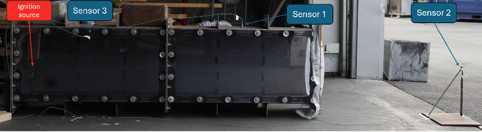

### **Test 4**

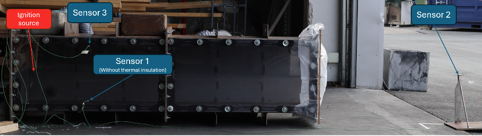

### **Test 5-7**

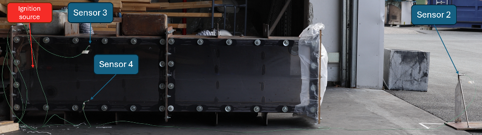

### **Test 8**

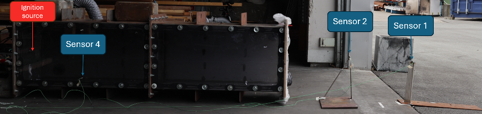

### **Test 9-11**

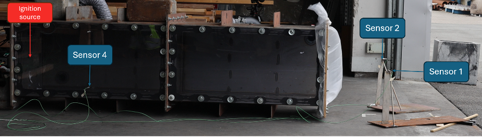

# Data Processing Procedure (DPP) Overview

**Units SI**

- **Data Preparation**

- **Exploratory Data Analysis (EDA)**

- **Preliminary Observations on Data Integrity**

- **Signal Preprocessing**

- **Quantity of Interest (QoI) Extraction of ∆Pmax [kPa] after Filtering**

- **Preliminary** **Conclusions and Suggestions**

## Matlab Startup File

This m-File code prepare the enviroment to provide access to auxilliary files and sub-folders.

clear all; clc; close all;
clear functions;
format short eng                              
% Plot Colors
LUCopper = [147, 86, 14]/255;LUCopper_Light = [225, 213, 199]/255;LUBlue = [17, 55, 125]/255;LUBlue_Light = [197, 204, 221]/255;
Red_Dark = [192, 0, 0]/255;Red_Light = [235, 200, 197]/255;pink = [255, 199, 206]/255;skyblue_light=[183/255 236/255 255/255];

## 1. Data Preparation 

### 1.1 Import Signal Data 

**Load Hydrogen Concentration "Raw" Signal**

**Objective:** import test-level H2 concentration targets and measured averages  for later interpretation and reporting.

**Workflow:**

- locate spreadsheet on MATLAB path

- read sheet while preserving original headers

- validate required columns

- standardize into analysis table (h2ConcTable)

- display imported table for verification

#### **1.1.1 Hydrogen Concentration (%V)**

**Note:** This section is required to retrieve the signal from the sensor or gas analyser in order to calculate the mean and standard deviation of the estimated concentration.

h2ConcFileName = 'Test_H2VConce.xlsx';
h2ConcFilePath = which(h2ConcFileName);
assert(~isempty(h2ConcFilePath), 'Hydrogen concentration file not found on MATLAB path: %s', h2ConcFileName);

% Keep original spreadsheet headers, then standardize to analysis-friendly names.
h2ConcOpts = detectImportOptions(h2ConcFilePath, 'FileType', 'spreadsheet');
h2ConcOpts.VariableNamingRule = 'preserve';
h2ConcRaw = readtable(h2ConcFilePath, h2ConcOpts);

assert(all(ismember(["Test #","Target Concentration [%]","avg measured conc.%"], string(h2ConcRaw.Properties.VariableNames))), ...
    'Unexpected columns in %s. Check spreadsheet headers.', h2ConcFileName);

h2TestLabel = string(strtrim(h2ConcRaw.("Test #")));
h2ConcTarget_pct = h2ConcRaw.("Target Concentration [%]");
h2ConcMeasuredAvg_pct = h2ConcRaw.("avg measured conc.%");

h2ConcTable = table(h2TestLabel, h2ConcTarget_pct, h2ConcMeasuredAvg_pct, ...
    'VariableNames', {'TestLabel','TargetConc_%','MeasuredConcAvg_%'});
disp(h2ConcTable);

    TestLabel    TargetConc_%    MeasuredConcAvg_%
    _________    ____________    _________________

    "test1"           18                17.5      
    "test2"           18                17.3      
    "test3"           18                17.4      
    "test4"           18                17.2      
    "test5"           18                17.4      
    "test6"           18                  17      
    "test7"           18               17.35      
    "test8"           18                17.4      
    "test9"           18                17.3      
    "test10"          18                17.4      
    "test11"          18                 NaN      



#### **1.1.2 Load Pressure "Raw" Signal**

**Objective:** import raw pressure/trigger signals for all selected tests and store them in a consistent format for downstream analyses.

**Workflow:**

- load selected txt files via auxiliary loader (DAQ1-only via AuxFcn_LoadExperiment)

- validate selected files are present

- store per-test metadata

**Note: **

- **DAQ Range: 5 bar.**Details on DAQ system setting are required, to check if any hardware filters has been used.

- Current analysis is channel-based (Y[0]..Y[3]).

- Sensor-to-channel mapping is pending confirmation from the experimental team.

- Keep channel labels neutral until mapping + calibration assignment are verified.

#### 1.1.2 Load Pressure "Raw" Signal

% --- Files to load (DAQ1 TXT) ---
selectedRawDataNames = { ...
    'Problem grounding.txt','Test 2.txt','test 3.txt','test 4.txt','test5.txt','test6.txt', ...
    'test7.txt','test8.txt','test9.txt','test10.txt','test11.txt'};

% --- Sanity: confirm auxiliaries exist on path ---
assert(exist('AuxFcn_LoadExperiment_003','file')==2, 'AuxFcn_LoadExperiment_003 not found on MATLAB path.');
assert(exist('AuxFcn_ReadDAQ_TXT_002','file')==2,     'AuxFcn_ReadDAQ_TXT_002 not found on MATLAB path.');

% --- Build cfg (DAQ1 only) ---
cfg = struct();
cfg.daqs(1).id     = "DAQ1";
cfg.daqs(1).format = "txt";
cfg.daqs(1).files  = selectedRawDataNames;
cfg.daqs(1).units  = ["bar","bar","bar","V"];
cfg.daqs(1).channelType = ["pressure","pressure","pressure","trigger"];
tests = AuxFcn_LoadExperiment_003(cfg);

% Identify which stream index corresponds to DAQ1 (assumes consistent cfg.daqs order)
daqsIds = string({tests(1).daqs.id});
kDAQ1 = find(daqsIds == "DAQ1", 1, 'first');
assert(~isempty(kDAQ1), 'DAQ1 stream not found in tests(1).daqs.');

% Pull DAQ1 data for all tests
selectedDataCell = arrayfun(@(s) s.daqs(kDAQ1).data, tests, 'UniformOutput', false);

validMask = ~cellfun(@isempty, selectedDataCell);
if any(~validMask)
    warning('DAQ1 missing for test indices: %s', mat2str(find(~validMask).'));
end

selectedData    = vertcat(selectedDataCell{validMask});  % struct array of daqData
selectedDataIdx = find(validMask).';
nTests = numel(selectedData);

% --- Summary table (as before) ---
loadedDataSummary = table( ...
    (1:nTests).', string({selectedData.fileName}).', ...
    [selectedData.nSamples].', [selectedData.nChannels].', ...
    [selectedData.fs].', [selectedData.dt].', ...
    'VariableNames', {'TestIdx','File','nSamples','nChannels','Fs_Hz','dt_s'});

disp(loadedDataSummary);

    TestIdx             File              nSamples    nChannels      Fs_Hz        dt_s  
    _______    _______________________    ________    _________    __________    _______

       1       "Problem grounding.txt"    6.25e+05        4        2.0833e+05    4.8e-06
       2       "Test 2.txt"               6.25e+05        4        2.0833e+05    4.8e-06
       3       "test 3.txt"               6.25e+05        4        2.0833e+05    4.8e-06
       4       "test 4.txt"               6.25e+05        4        2.0833e+05    4.8e-06
       5       "test5.txt"                6.25e+05        4        2.0833e+05    4.8e-06
       6       "test6.txt"                6.25e+05        4        2.0833e+05    4.8e-06
       7       "test7.txt"                6.25e+05        4        2.0833e+05    4.

### 1.2 Plot Imported Signal Data 

**Objective:** visually screen all tests/channels and highlight known regions of interest (trigger EMI and early-time channel behavior).

**Workflow:**

- loop through tests and skip those with insufficient channels

- extract first 4 channels and convert pressure channels to kPa

- plot stacked channel subplots with consistent labels/format

- add focused insets for channel-4 EMI and Test-1/channel-1 window

**Note: **using subplots for simultaneous visualization of all channels.

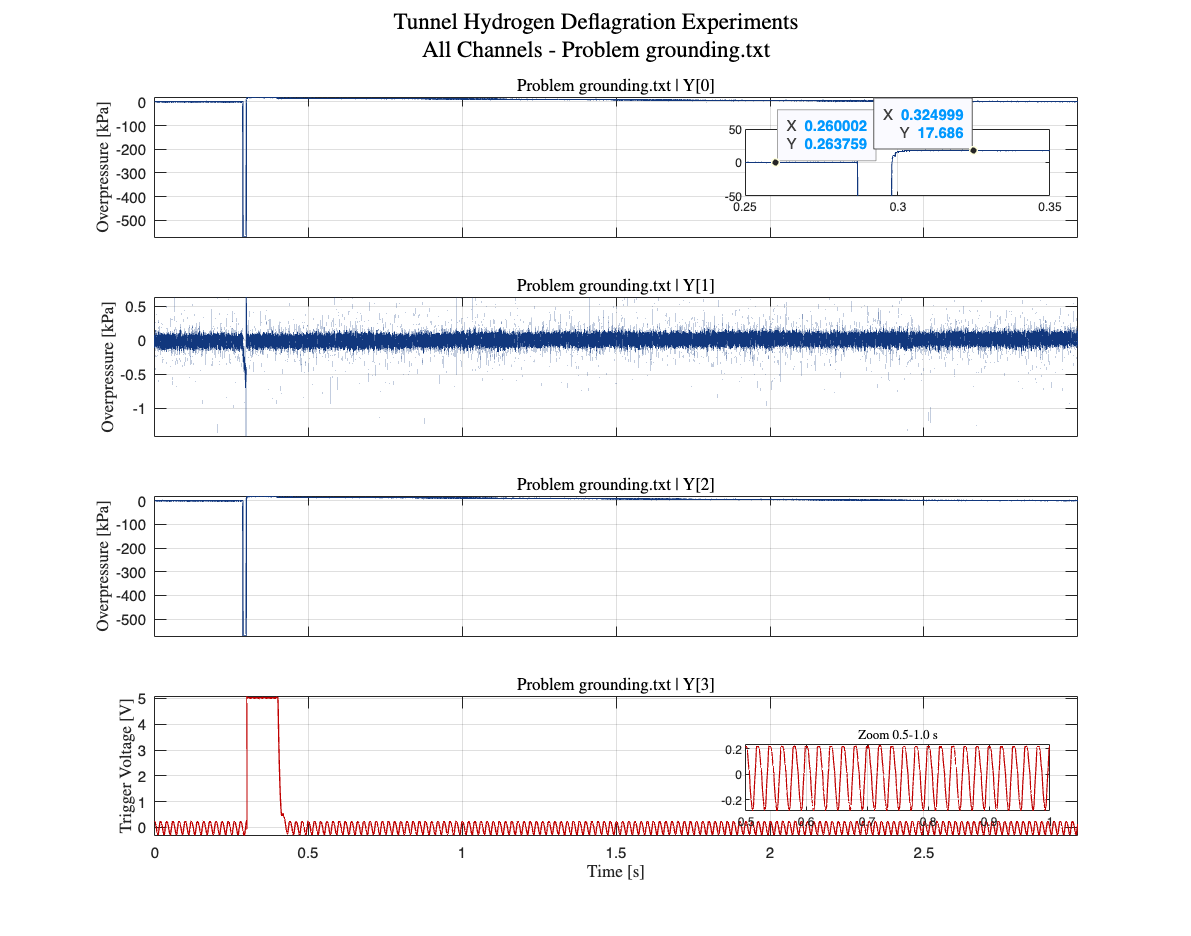

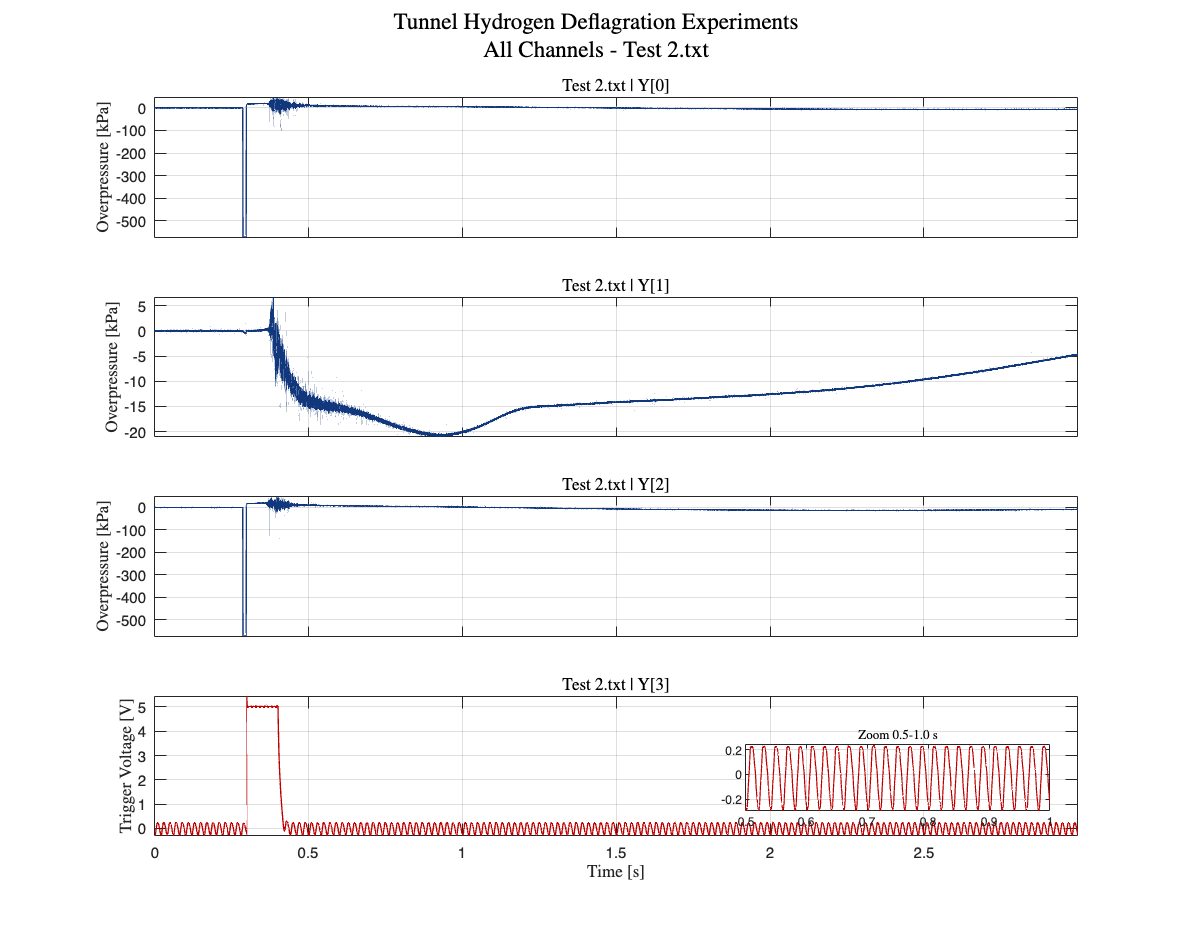

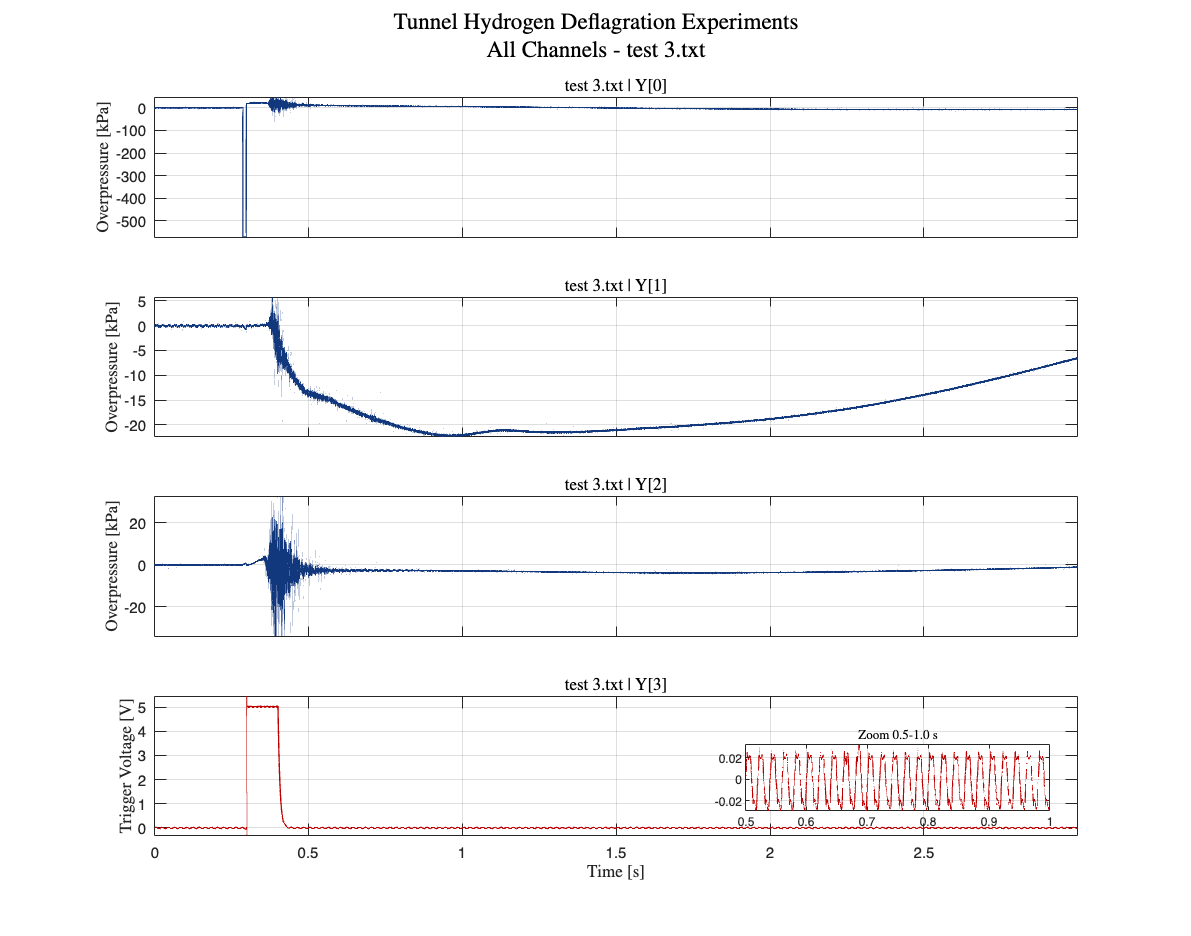

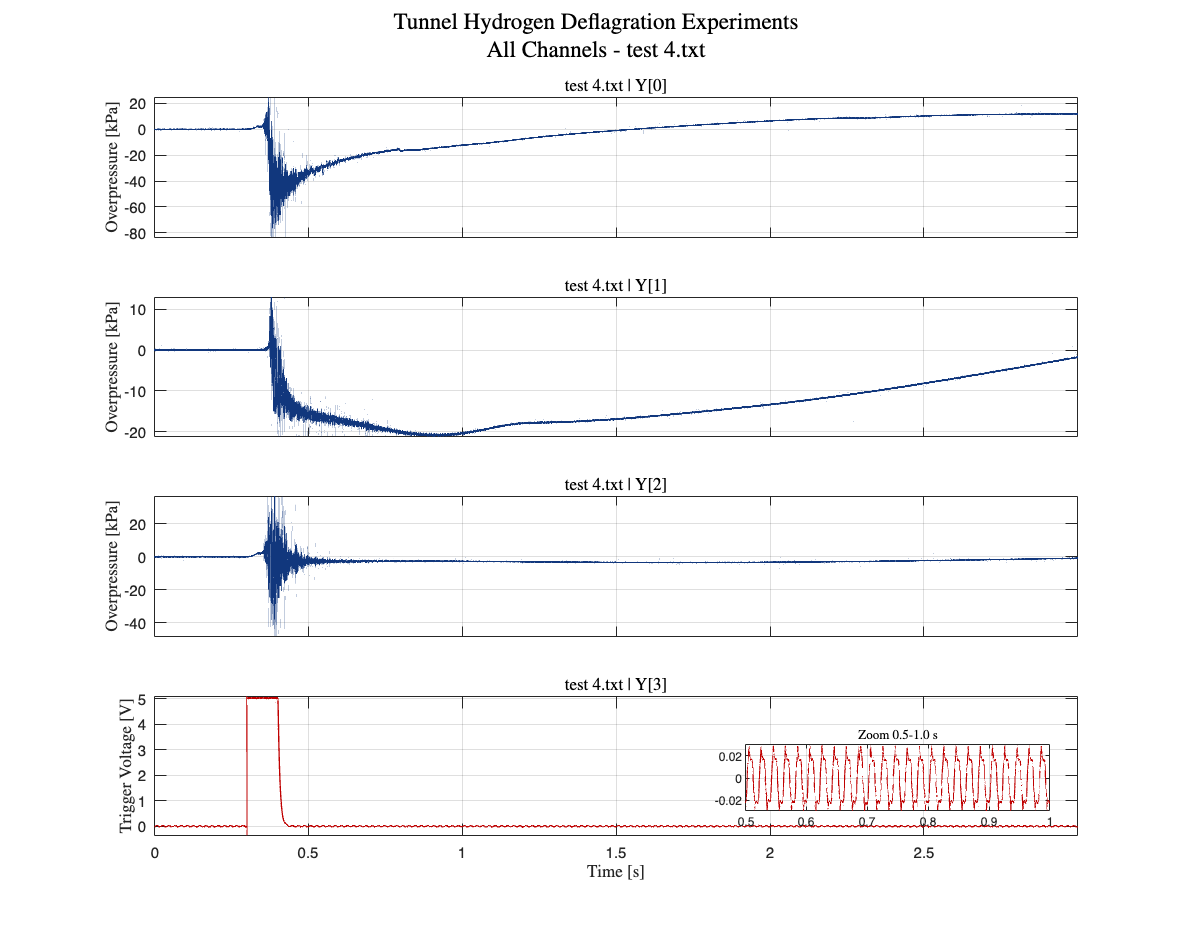

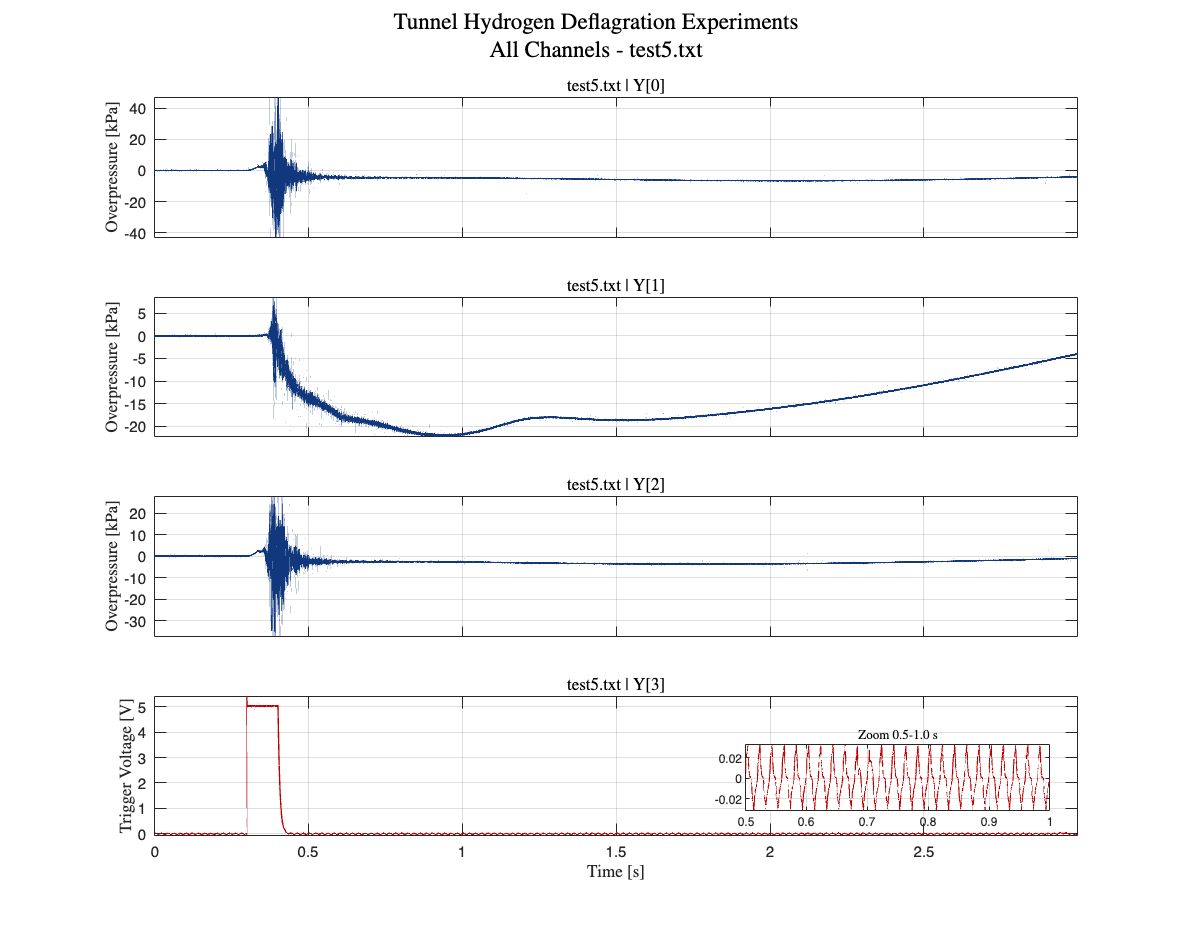

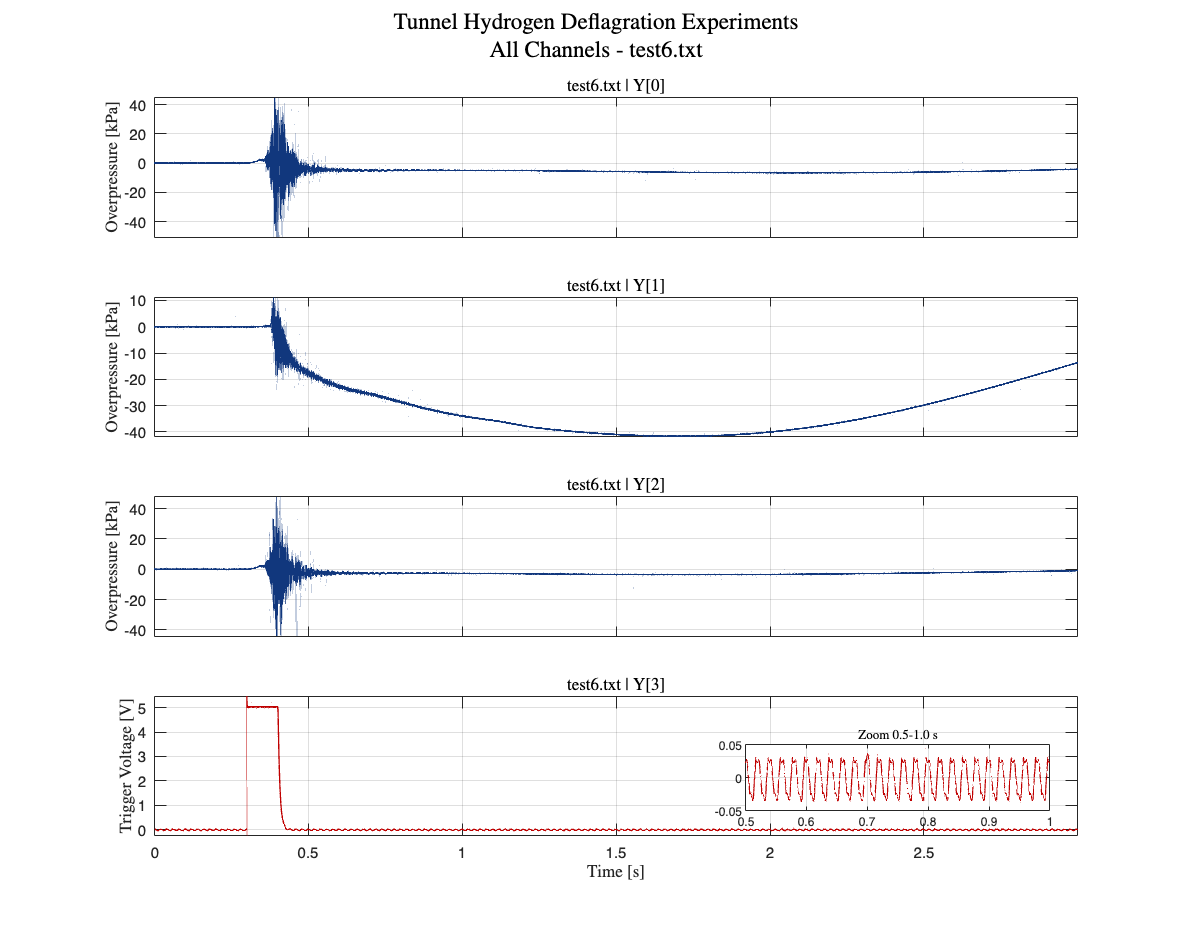

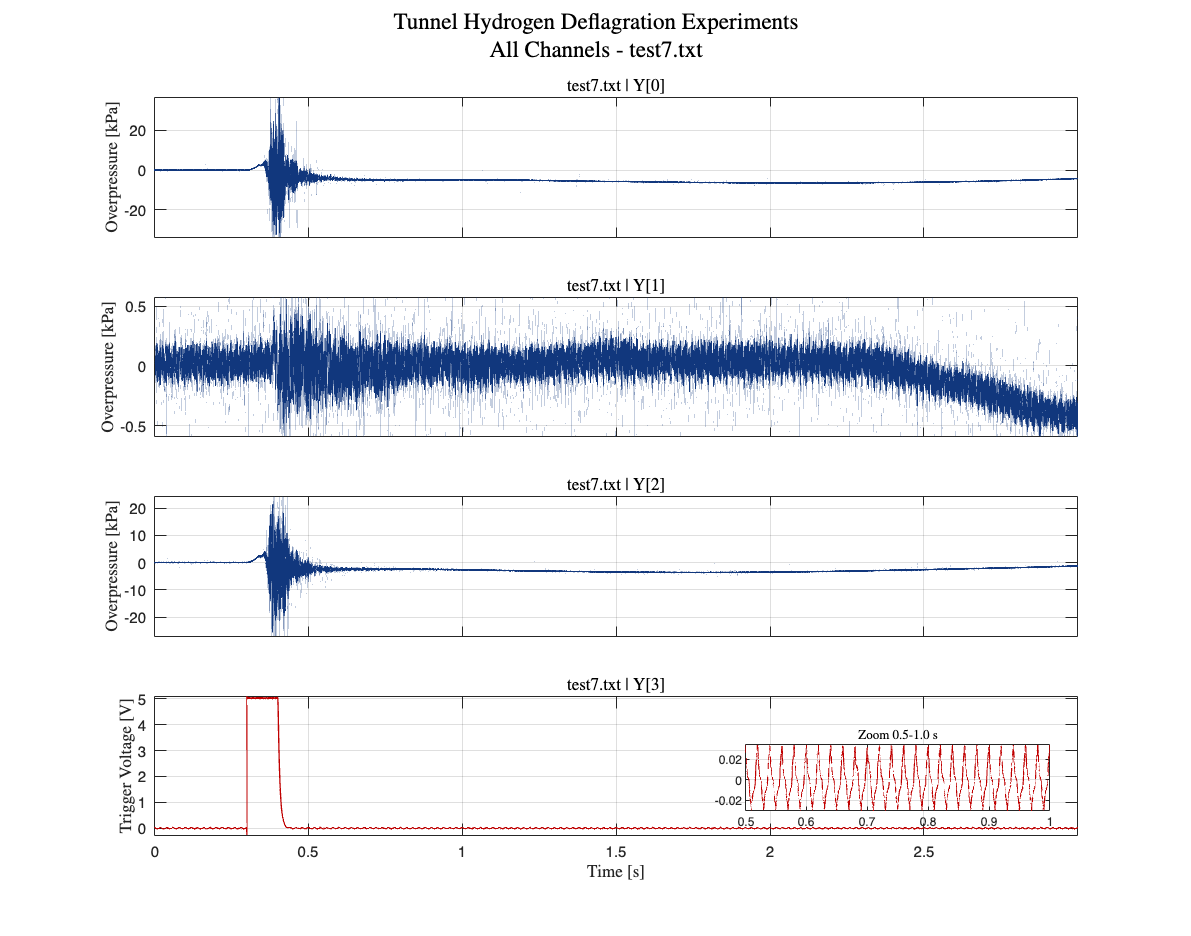

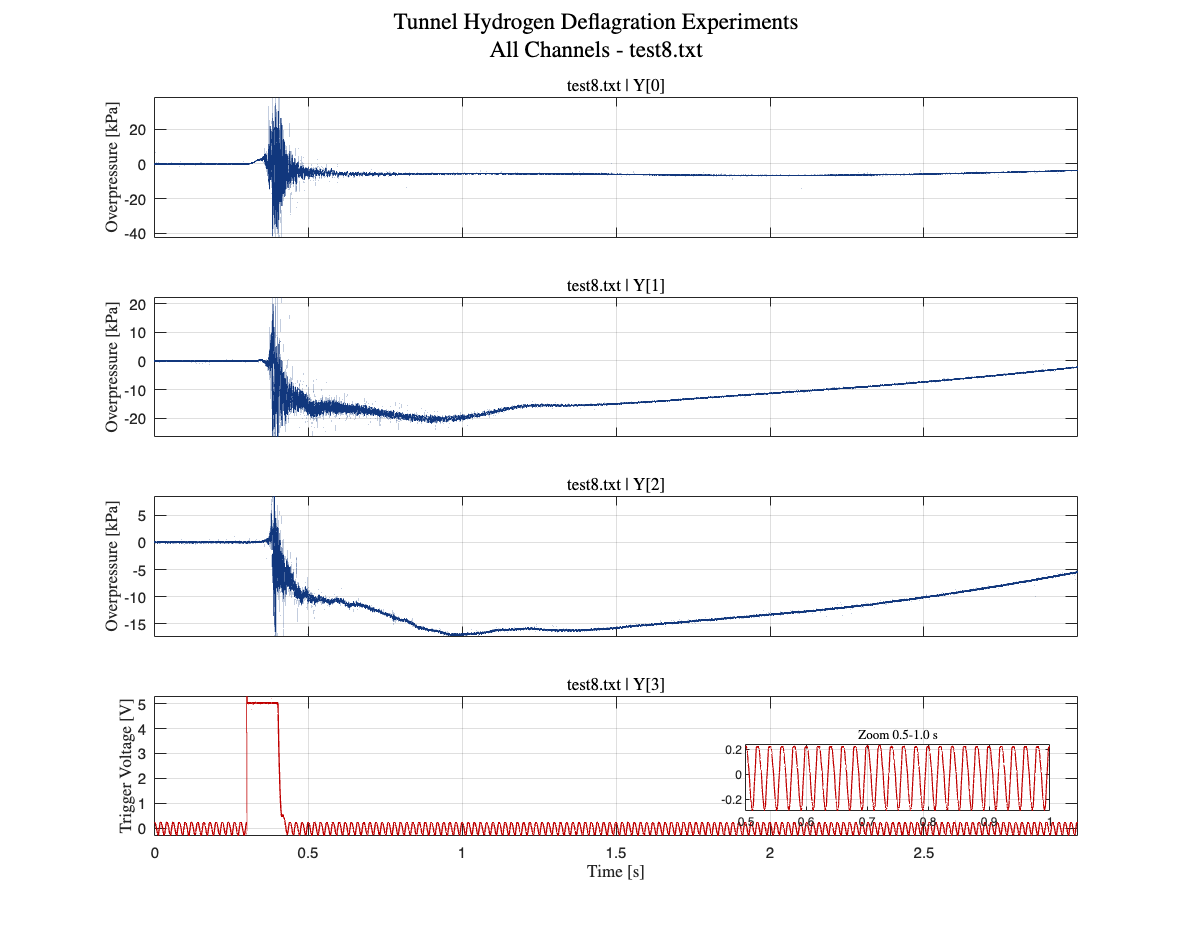

daqIdx = 1; % Primary DAQ source index 

for testIdx = 1:numel(tests)
    daqData = tests(testIdx).daqs(daqIdx).data;
    
    if isempty(daqData) || daqData.nChannels < 4
        if ~isempty(daqData)
             warning('Skipping %s: found only %d channels.', daqData.fileName, daqData.nChannels);
        end
        continue;
    end

    t_test = daqData.t;       
    y_all  = daqData.signal;  
    y_test = y_all(:, 1:4);
    y_test(:, 1:3) = y_test(:, 1:3) * 100; 

    figure;
    x0 = 10; y0 = 10; width = 28; height = 22;
    set(gcf, 'units', 'centimeters', 'position', [x0, y0, width, height]);
    sgtitle({ ...
        'Tunnel Hydrogen Deflagration Experiments'; ...
        sprintf('All Channels - %s', daqData.fileName) ... 
        }, 'Interpreter', 'latex');

    for chIdx = 1:4
        ax = subplot(4,1,chIdx);
        
        if chIdx == 4
            thisColor = Red_Dark; 
        else
            thisColor = LUBlue;
        end
        
        hLine = plot(t_test, y_test(:,chIdx), 'Color', thisColor, 'LineWidth', 0.9);
        grid on; axis tight;
        
        thisChName = daqData.channelNames(chIdx);
        title(sprintf('%s | %s', daqData.fileName, thisChName), 'Interpreter', 'latex');

        if chIdx <= 3
            ylabel('Overpressure [kPa]', 'Interpreter', 'latex');
        else
            ylabel('Trigger Voltage [V]', 'Interpreter', 'latex');
        end

        if chIdx < 4
            set(gca, 'xticklabel', []);
        else
            xlabel('Time [s]', 'Interpreter', 'latex');
        end

        % --- Inset Logic ---
        if chIdx == 4
            % Highlight electrical interference (No datatips needed here)
            localAddInset(ax, t_test, y_test(:,chIdx), [0.5, 1.0], 'Zoom 0.5-1.0 s', thisColor);
        end

        if testIdx == 1 && chIdx == 1
            % Focused inset for Test 1, Channel 1 
            % Return both the inset axes and the line handle [axIn, hInLine]
            [axInT1C1, hInLine] = localAddInset(ax, t_test, y_test(:,chIdx), [0.25, 0.35], 'Zoom 0.275-0.30 s', thisColor);
            
            if ~isempty(axInT1C1)
                ylim(axInT1C1, [-50, 50]);
                
                % Add datatips to the INSET line handle (hInLine)
                tipTimes = [0.26, 0.325];
                for iTip = 1:numel(tipTimes)
                    [~, idxTip] = min(abs(t_test - tipTimes(iTip)));
                    % Citing the corrected placement logic: use hInLine for the inset datatip
                    datatip(hInLine, t_test(idxTip), y_test(idxTip, chIdx));
                end
            end
        end
    end
end


%% Helper Function for Insets (Updated to return line handle)
function [axIn, hInLine] = localAddInset(parentAx, t, y, zoomWin, lbl, col)
    axIn = [];
    hInLine = [];
    idx = t >= zoomWin(1) & t <= zoomWin(2);
    if any(idx)
        p = parentAx.Position;
        axIn = axes('Position', [p(1)+0.64*p(3), p(2)+0.15*p(4), 0.33*p(3), 0.45*p(4)]);
        % Store the line handle created in the inset axes
        hInLine = plot(axIn, t(idx), y(idx), 'Color', col, 'LineWidth', 0.8);
        grid(axIn, 'on'); 
        xlim(axIn, zoomWin);
        title(axIn, lbl, 'FontSize', 8, 'Interpreter', 'latex');
        set(axIn, 'FontSize', 8);
    end
end

## 2. Exploratory Data Analysis (EDA)

### **2.1 Sample Rate Verification**

**Objective: **verify reported metadata in the generated .txt dat file and compare against DAQ system datasheet and samples time stamps.

**Workflow (Outputs to track):**

- samplingRateSummary     -> metadata vs timestamps vs datasheet

- timingUncertainty       -> mean/std/u/U95 from timestamp deltas

- samplingRateDiffSummary -> relative differences (%)

daqIdx = 1; % Index of the TXT DAQ to verify
samplingRateResults = struct([]);

for iTest = 1:numel(tests)
    thisData = tests(iTest).daqs(daqIdx).data;
    
    % Only perform verification if data exists and contains the raw table (TXT files)
    if isempty(thisData) || ~isfield(thisData, 'tbl')
        continue;
    end

    % Call the new version of the auxiliary function
    [samplingRateSummary_i, timingUncertainty_i, samplingRateDiffSummary_i, samplingRateMetrics_i] = ...
        AuxFcn_SamplingRateVerification_001(thisData.tbl, thisData.dt, thisData.fs, 200e3, 2);

    % Store results using the new fileName field
    samplingRateResults(iTest).fileName = thisData.fileName;
    samplingRateResults(iTest).samplingRateSummary = samplingRateSummary_i;
    samplingRateResults(iTest).timingUncertainty = timingUncertainty_i;
    samplingRateResults(iTest).samplingRateDiffSummary = samplingRateDiffSummary_i;
    samplingRateResults(iTest).samplingRateMetrics = samplingRateMetrics_i;

    fprintf('\n--- Sample-rate verification: %s ---\n', thisData.fileName);
    disp(samplingRateSummary_i);
    disp(timingUncertainty_i);
    disp(samplingRateDiffSummary_i);

    % Check for discrepancies (> 1%)
    if abs(samplingRateMetrics_i.fsDiff_timeMean_vs_meta_pct) > 1
        warning('[%s] Timestamp mean fs and metadata fs differ by more than 1%%.', thisData.fileName);
    end

    if abs(samplingRateMetrics_i.fsDiff_meta_vs_datasheet_pct) > 1
        warning(['[%s] Metadata fs differs from datasheet nominal value by %.4f%% ' ...
            '(metadata: %.3f Hz, datasheet: %.3f Hz).'], ...
            thisData.fileName, samplingRateMetrics_i.fsDiff_meta_vs_datasheet_pct, ...
            thisData.fs, samplingRateMetrics_i.fsDataSheet);
    end
end


--- Sample-rate verification: Problem grounding.txt ---


          Source            dt_s        fs_Hz   
    ___________________    _______    __________

    "Metadata"             4.8e-06    2.0833e+05
    "Timestamps (Mean)"    4.8e-06    2.0833e+05
    "Datasheet"              5e-06         2e+05



    nIntervals     std_dt_s     u_dt_mean_s    U95_dt_mean_s    u_fs_mean_Hz    U95_fs_mean_Hz
    __________    __________    ___________    _____________    ____________    ______________

     6.25e+05     3.9999e-07    5.0596e-10      1.0119e-09         21.96            43.92     



          Comparison           dtDiff_pct     fsDiff_pct
    _______________________    ___________    __________

    "TimeMean vs Metadata"     -1.3333e-05    1.3333e-05
    "Metadata vs Datasheet"        -3.9998        4.1665
    "TimeMean vs Datasheet"        -3.9999        4.1665




--- Sample-rate verification: Test 2.txt ---


          Source            dt_s        fs_Hz   
    ___________________    _______    __________

    "Metadata"             4.8e-06    2.0833e+05
    "Timestamps (Mean)"    4.8e-06    2.0833e+05
    "Datasheet"              5e-06         2e+05



    nIntervals     std_dt_s     u_dt_mean_s    U95_dt_mean_s    u_fs_mean_Hz    U95_fs_mean_Hz
    __________    __________    ___________    _____________    ____________    ______________

     6.25e+05     3.9999e-07    5.0596e-10      1.0119e-09         21.96            43.92     



          Comparison           dtDiff_pct     fsDiff_pct
    _______________________    ___________    __________

    "TimeMean vs Metadata"     -1.3333e-05    1.3333e-05
    "Metadata vs Datasheet"        -3.9998        4.1665
    "TimeMean vs Datasheet"        -3.9999        4.1665




--- Sample-rate verification: test 3.txt ---


          Source            dt_s        fs_Hz   
    ___________________    _______    __________

    "Metadata"             4.8e-06    2.0833e+05
    "Timestamps (Mean)"    4.8e-06    2.0833e+05
    "Datasheet"              5e-06         2e+05



    nIntervals     std_dt_s     u_dt_mean_s    U95_dt_mean_s    u_fs_mean_Hz    U95_fs_mean_Hz
    __________    __________    ___________    _____________    ____________    ______________

     6.25e+05     3.9999e-07    5.0596e-10      1.0119e-09         21.96            43.92     



          Comparison           dtDiff_pct     fsDiff_pct
    _______________________    ___________    __________

    "TimeMean vs Metadata"     -1.3333e-05    1.3333e-05
    "Metadata vs Datasheet"        -3.9998        4.1665
    "TimeMean vs Datasheet"        -3.9999        4.1665




--- Sample-rate verification: test 4.txt ---


          Source            dt_s        fs_Hz   
    ___________________    _______    __________

    "Metadata"             4.8e-06    2.0833e+05
    "Timestamps (Mean)"    4.8e-06    2.0833e+05
    "Datasheet"              5e-06         2e+05



    nIntervals     std_dt_s     u_dt_mean_s    U95_dt_mean_s    u_fs_mean_Hz    U95_fs_mean_Hz
    __________    __________    ___________    _____________    ____________    ______________

     6.25e+05     3.9999e-07    5.0596e-10      1.0119e-09         21.96            43.92     



          Comparison           dtDiff_pct     fsDiff_pct
    _______________________    ___________    __________

    "TimeMean vs Metadata"     -1.3333e-05    1.3333e-05
    "Metadata vs Datasheet"        -3.9998        4.1665
    "TimeMean vs Datasheet"        -3.9999        4.1665




--- Sample-rate verification: test5.txt ---


          Source            dt_s        fs_Hz   
    ___________________    _______    __________

    "Metadata"             4.8e-06    2.0833e+05
    "Timestamps (Mean)"    4.8e-06    2.0833e+05
    "Datasheet"              5e-06         2e+05



    nIntervals     std_dt_s     u_dt_mean_s    U95_dt_mean_s    u_fs_mean_Hz    U95_fs_mean_Hz
    __________    __________    ___________    _____________    ____________    ______________

     6.25e+05     3.9999e-07    5.0596e-10      1.0119e-09         21.96            43.92     



          Comparison           dtDiff_pct     fsDiff_pct
    _______________________    ___________    __________

    "TimeMean vs Metadata"     -1.3333e-05    1.3333e-05
    "Metadata vs Datasheet"        -3.9998        4.1665
    "TimeMean vs Datasheet"        -3.9999        4.1665




--- Sample-rate verification: test6.txt ---


          Source            dt_s        fs_Hz   
    ___________________    _______    __________

    "Metadata"             4.8e-06    2.0833e+05
    "Timestamps (Mean)"    4.8e-06    2.0833e+05
    "Datasheet"              5e-06         2e+05



    nIntervals     std_dt_s     u_dt_mean_s    U95_dt_mean_s    u_fs_mean_Hz    U95_fs_mean_Hz
    __________    __________    ___________    _____________    ____________    ______________

     6.25e+05     3.9999e-07    5.0596e-10      1.0119e-09         21.96            43.92     



          Comparison           dtDiff_pct     fsDiff_pct
    _______________________    ___________    __________

    "TimeMean vs Metadata"     -1.3333e-05    1.3333e-05
    "Metadata vs Datasheet"        -3.9998        4.1665
    "TimeMean vs Datasheet"        -3.9999        4.1665




--- Sample-rate verification: test7.txt ---


          Source            dt_s        fs_Hz   
    ___________________    _______    __________

    "Metadata"             4.8e-06    2.0833e+05
    "Timestamps (Mean)"    4.8e-06    2.0833e+05
    "Datasheet"              5e-06         2e+05



    nIntervals     std_dt_s     u_dt_mean_s    U95_dt_mean_s    u_fs_mean_Hz    U95_fs_mean_Hz
    __________    __________    ___________    _____________    ____________    ______________

     6.25e+05     3.9999e-07    5.0596e-10      1.0119e-09         21.96            43.92     



          Comparison           dtDiff_pct     fsDiff_pct
    _______________________    ___________    __________

    "TimeMean vs Metadata"     -1.3333e-05    1.3333e-05
    "Metadata vs Datasheet"        -3.9998        4.1665
    "TimeMean vs Datasheet"        -3.9999        4.1665




--- Sample-rate verification: test8.txt ---


          Source            dt_s        fs_Hz   
    ___________________    _______    __________

    "Metadata"             4.8e-06    2.0833e+05
    "Timestamps (Mean)"    4.8e-06    2.0833e+05
    "Datasheet"              5e-06         2e+05



    nIntervals     std_dt_s     u_dt_mean_s    U95_dt_mean_s    u_fs_mean_Hz    U95_fs_mean_Hz
    __________    __________    ___________    _____________    ____________    ______________

     6.25e+05     3.9999e-07    5.0596e-10      1.0119e-09         21.96            43.92     



          Comparison           dtDiff_pct     fsDiff_pct
    _______________________    ___________    __________

    "TimeMean vs Metadata"     -1.3333e-05    1.3333e-05
    "Metadata vs Datasheet"        -3.9998        4.1665
    "TimeMean vs Datasheet"        -3.9999        4.1665




--- Sample-rate verification: test9.txt ---


          Source            dt_s        fs_Hz   
    ___________________    _______    __________

    "Metadata"             4.8e-06    2.0833e+05
    "Timestamps (Mean)"    4.8e-06    2.0833e+05
    "Datasheet"              5e-06         2e+05



    nIntervals     std_dt_s     u_dt_mean_s    U95_dt_mean_s    u_fs_mean_Hz    U95_fs_mean_Hz
    __________    __________    ___________    _____________    ____________    ______________

     6.25e+05     3.9999e-07    5.0596e-10      1.0119e-09         21.96            43.92     



          Comparison           dtDiff_pct     fsDiff_pct
    _______________________    ___________    __________

    "TimeMean vs Metadata"     -1.3333e-05    1.3333e-05
    "Metadata vs Datasheet"        -3.9998        4.1665
    "TimeMean vs Datasheet"        -3.9999        4.1665




--- Sample-rate verification: test10.txt ---


          Source            dt_s        fs_Hz   
    ___________________    _______    __________

    "Metadata"             4.8e-06    2.0833e+05
    "Timestamps (Mean)"    4.8e-06    2.0833e+05
    "Datasheet"              5e-06         2e+05



    nIntervals     std_dt_s     u_dt_mean_s    U95_dt_mean_s    u_fs_mean_Hz    U95_fs_mean_Hz
    __________    __________    ___________    _____________    ____________    ______________

     6.25e+05     3.9999e-07    5.0596e-10      1.0119e-09         21.96            43.92     



          Comparison           dtDiff_pct     fsDiff_pct
    _______________________    ___________    __________

    "TimeMean vs Metadata"     -1.3333e-05    1.3333e-05
    "Metadata vs Datasheet"        -3.9998        4.1665
    "TimeMean vs Datasheet"        -3.9999        4.1665




--- Sample-rate verification: test11.txt ---


          Source            dt_s        fs_Hz   
    ___________________    _______    __________

    "Metadata"             4.8e-06    2.0833e+05
    "Timestamps (Mean)"    4.8e-06    2.0833e+05
    "Datasheet"              5e-06         2e+05



    nIntervals     std_dt_s     u_dt_mean_s    U95_dt_mean_s    u_fs_mean_Hz    U95_fs_mean_Hz
    __________    __________    ___________    _____________    ____________    ______________

     6.25e+05     3.9999e-07    5.0596e-10      1.0119e-09         21.96            43.92     



          Comparison           dtDiff_pct     fsDiff_pct
    _______________________    ___________    __________

    "TimeMean vs Metadata"     -1.3333e-05    1.3333e-05
    "Metadata vs Datasheet"        -3.9998        4.1665
    "TimeMean vs Datasheet"        -3.9999        4.1665



### **2.2 Pressure Sensors Signal Verification (**Data Integrity Verification)

**Objective: **verify the impact of the ignition mechanism (Channel 4 (Y)) on pressure sensors. Time when ignition tigger

**Workflow:**

- extract Test 1 pressure channel (Y[0]) and trigger channel (Y[3])

- convert pressure to kPa

- plot both channels with dual y-axes for time alignment check

#### 2.2.1 Igntion **Trigger Misalignment & Synchronization Failure**

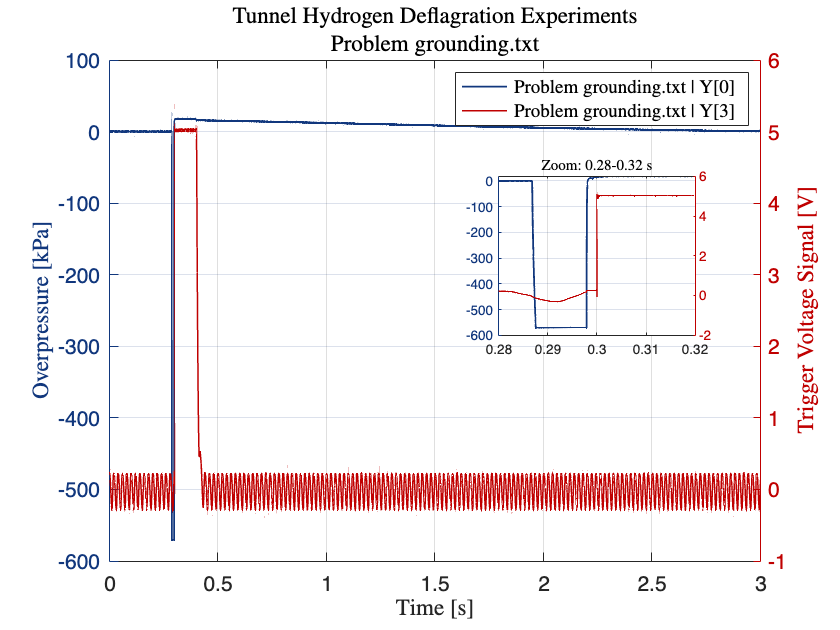

testIdx = 1; 
daqIdx  = 1; 

% Access data using the descriptive 'daqs' field
daqData = tests(testIdx).daqs(daqIdx).data; 

if ~isempty(daqData) && daqData.nChannels >= 4
    % Extract signals from standardized fields 
    t_test = daqData.t;       
    
    % Pressure (Ch 1) and Trigger (Ch 4)
    y_pressure = daqData.signal(:, 1) * 100; % Convert to kPa
    y_trigger  = daqData.signal(:, 4);
    
    % Prepare LaTeX-safe labels
    label_Ch1 = sprintf('%s | %s', daqData.fileName, daqData.channelNames(1));
    label_Ch4 = sprintf('%s | %s', daqData.fileName, daqData.channelNames(4));

    figure; 
    set(gcf,'color','w');
    colororder([LUBlue; Red_Dark]);
    
    % --- Main Plot: Left Axis ---
    yyaxis left
    plot(t_test, y_pressure, 'LineWidth', 1.2); 
    ylabel('Overpressure [kPa]', 'Interpreter', 'latex');
    
    % --- Main Plot: Right Axis ---
    yyaxis right
    plot(t_test, y_trigger, 'LineWidth', 1.0);
    ylabel('Trigger Voltage Signal [V]', 'Interpreter', 'latex');
    
    xlabel('Time [s]', 'Interpreter', 'latex');
    title({'Tunnel Hydrogen Deflagration Experiments', daqData.fileName}, 'Interpreter', 'latex');
    legend({label_Ch1, label_Ch4}, 'Location', 'northeast', 'Interpreter', 'latex');
    
    set(gca, 'FontName', "Helvetica", 'FontSize', 14);
    grid on; box on;

    % --- INSERT ZOOM INSET (0.28 - 0.32 s) ---
    zoomWin = [0.28, 0.32];
    idxZoom = (t_test >= zoomWin(1) & t_test <= zoomWin(2));
    
    if any(idxZoom)
        % Position the inset axes (Top-center area)
        axMain = gca;
        axPos = axMain.Position;
        % [left, bottom, width, height]
        axIn = axes('Position', [axPos(1)+0.60*axPos(3), axPos(2)+0.45*axPos(4), 0.35*axPos(3), 0.40*axPos(4)]);
        
        % Plot Dual Y-Axis inside the inset
        yyaxis(axIn, 'left');
        plot(axIn, t_test(idxZoom), y_pressure(idxZoom), 'LineWidth', 1.2);
        set(axIn, 'YColor', LUBlue); % Ensure color consistency
        
        yyaxis(axIn, 'right');
        plot(axIn, t_test(idxZoom), y_trigger(idxZoom), 'LineWidth', 1.0);
        set(axIn, 'YColor', Red_Dark);
        
        % Inset Formatting
        xlim(axIn, zoomWin);
        grid(axIn, 'on');
        title(axIn, 'Zoom: 0.28-0.32 s', 'FontSize', 10, 'Interpreter', 'latex');
        set(axIn, 'FontSize', 9);
    end
end

### **2.3  Trigger Signal Verification (EMI Interferance & Trigger Pulse Width)**

(Trigger Noise Frequency Verification)

**Objective: **verify whether trigger-channel oscillation in Test 1 is consistent with 50 Hz power-line EMI (Europe).

**Workflow:**

- isolate the suspect interval (0.5-1.0 s) from Test 1, Channel 4

- remove DC offset and apply Hann window (lower spectral leakage)

- compute the single-sided FFT amplitude spectrum

- quantify peaks near 50 Hz and in a broader 40-80 Hz band

- plot time-domain segment + spectrum with 50/100/150 Hz references

#### 2.3.1 Selected Data

emiTestIdx = 1;          % Test used for EMI check
emiDaqIdx  = 1;          % Standardized DAQ stream
emiChIdx   = 4;          % Channel 4 -> Y[3] trigger signal
emiWindow  = [0.5, 1.0]; % Analysis time window [s]

% Extract the standardized daqData object
daqDataEMI = tests(emiTestIdx).daqs(emiDaqIdx).data;

% Verify the required channel exists in the selected DAQ
assert(~isempty(daqDataEMI) && daqDataEMI.nChannels >= emiChIdx, ...
    'Selected DAQ does not contain channel %d.', emiChIdx);

% --- EXPLICIT CALL: 'false' means we want raw Volts, no conversion ---
[t_emi, y_emi, fs_emi] = AuxFcn_GetWindowedSignal_001(daqDataEMI, emiChIdx, emiWindow, false);
N_emi = numel(y_emi);


#### 2.3.2 Remove DC Offset and Taper

y_emi_detr = y_emi - mean(y_emi, 'omitnan');
w_emi = hann(N_emi, 'periodic'); % see note on Hanning(Hann) window
y_emi_win = y_emi_detr .* w_emi;

#### 2.3.3 Compute FFT

FFT to one-sided amplitude spectrum (resolution = fs_emi/N_emi)

Y_emi = fft(y_emi_win);
P2_emi = abs(Y_emi / (N_emi * mean(w_emi))); % Added mean(w_emi) to recover the True Amplitude in Volts
P1_emi = P2_emi(1:floor(N_emi/2)+1);
if numel(P1_emi) > 2
    P1_emi(2:end-1) = 2 * P1_emi(2:end-1);
end
f_emi = fs_emi * (0:floor(N_emi/2)) / N_emi;

#### 2.3.4 Quantify Frequency Peaks

% Peak search around nominal mains frequency
searchBW = 2;  % +/- Hz around 50 Hz
idx50 = f_emi >= (50 - searchBW) & f_emi <= (50 + searchBW);

f50_peak = NaN; A50_peak = NaN;
if any(idx50)
    [A50_peak, i50] = max(P1_emi(idx50));
    f50_vec = f_emi(idx50);
    f50_peak = f50_vec(i50);
end

% Identify dominant component in a broader EMI band
emiBand = [40, 80];
idxBand = f_emi >= emiBand(1) & f_emi <= emiBand(2);
f_dom = NaN; A_dom = NaN;
if any(idxBand)
    [A_dom, iDom] = max(P1_emi(idxBand));
    fBand = f_emi(idxBand);
    f_dom = fBand(iDom);
end

fprintf('\n--- EMI verification (%s, Trigger Channel %d, %.3f-%.3f s) ---\n', ...
    daqDataEMI.fileName, emiChIdx, emiWindow(1), emiWindow(2));


--- EMI verification (Problem grounding.txt, Trigger Channel 4, 0.500-1.000 s) ---


fprintf('Peak near 50 Hz: f = %.3f Hz, A = %.5g\n', f50_peak, A50_peak);

Peak near 50 Hz: f = 50.000 Hz, A = 0.25402


fprintf('Dominant peak in %.0f-%.0f Hz band: f = %.3f Hz, A = %.5g\n', ...
    emiBand(1), emiBand(2), f_dom, A_dom);

Dominant peak in 40-80 Hz band: f = 50.000 Hz, A = 0.25402


% --- Calculate Harmonics and Prominence ---
idx100 = f_emi >= (100 - searchBW) & f_emi <= (100 + searchBW);
idx150 = f_emi >= (150 - searchBW) & f_emi <= (150 + searchBW);
f100_peak = NaN; A100_peak = NaN;
f150_peak = NaN; A150_peak = NaN;

if any(idx100)
    [A100_peak, i100] = max(P1_emi(idx100));
    f100_vec = f_emi(idx100);
    f100_peak = f100_vec(i100);
end
if any(idx150)
    [A150_peak, i150] = max(P1_emi(idx150));
    f150_vec = f_emi(idx150);
    f150_peak = f150_vec(i150);
end

idxBandNo50 = idxBand & ~(f_emi >= (50 - searchBW) & f_emi <= (50 + searchBW));
A_band_no50 = P1_emi(idxBandNo50);
if isempty(A_band_no50)
    A_band_no50_med = NaN;
else
    A_band_no50_med = median(A_band_no50, 'omitnan');
end
prominence50 = A50_peak / A_band_no50_med;

% Compact summary table
emiSummaryTable = table( ...
    emiTestIdx, emiChIdx, emiWindow(1), emiWindow(2), ...
    f50_peak, A50_peak, f100_peak, A100_peak, f150_peak, A150_peak, ...
    f_dom, A_dom, prominence50, ...
    'VariableNames', { ...
    'TestIdx','ChannelIdx','WindowStart_s','WindowEnd_s', ...
    'Peak50_Hz','Amp50_V','Peak100_Hz','Amp100_V','Peak150_Hz','Amp150_V', ...
    'Dominant40to80_Hz','Dominant40to80Amp_V','Prominence50_vsBandMedian'});
disp(emiSummaryTable);

    TestIdx    ChannelIdx    WindowStart_s    WindowEnd_s    Peak50_Hz    Amp50_V    Peak100_Hz    Amp100_V    Peak150_Hz    Amp150_V     Dominant40to80_Hz    Dominant40to80Amp_V    Prominence50_vsBandMedian
    _______    __________    _____________    ___________    _________    _______    __________    ________    __________    _________    _________________    ___________________    _________________________

       1           4              0.5              1            50        0.25402       100        0.036097       150        0.0057256       

% Interpretation Logic
if ~isnan(f_dom) && abs(f_dom - 50) <= 1.5 && ~isnan(prominence50) && prominence50 >= 10
    emiInterpretation = sprintf(['EMI conclusion: Strong evidence of 50 Hz mains interference ' ...
        '(dominant %.2f Hz; prominence %.1fx above 40-80 Hz median excluding 50 Hz).'], ...
        f_dom, prominence50);
elseif ~isnan(f_dom) && abs(f_dom - 50) <= 3
    emiInterpretation = sprintf(['EMI conclusion: Likely 50 Hz mains interference ' ...
        '(dominant %.2f Hz), but with weaker separation from background.'], f_dom);
else
    emiInterpretation = sprintf(['EMI conclusion: Inconclusive for 50 Hz dominance ' ...
        '(dominant %.2f Hz in 40-80 Hz band).'], f_dom);
end
fprintf('%s\n', emiInterpretation);

EMI conclusion: Strong evidence of 50 Hz mains interference (dominant 50.00 Hz; prominence 596.9x above 40-80 Hz median excluding 50 Hz).


#### 2.3.5 Trigger Pulse Width Verification

% Extract the entire trigger signal to locate the actual pulse
t_full = daqDataEMI.t;
y_full = daqDataEMI.signal(:, emiChIdx);

% Define logical threshold for 5V TTL (2.5V is industry standard)
trigThreshold = 2.5; 
isHigh = y_full >= trigThreshold;

% Find edge indices (diff = 1 for rising, -1 for falling)
edgeEvents = diff(isHigh);
idxRise = find(edgeEvents == 1, 1, 'first');
idxFall = find(edgeEvents == -1, 1, 'first');

if ~isempty(idxRise) && ~isempty(idxFall) && (idxFall > idxRise)
    t_rise = t_full(idxRise);
    t_fall = t_full(idxFall);
    pulseWidth_s = t_fall - t_rise; % Keep in seconds for ratio math
    
    % Calculate minimum required pulse based on sampling rate
    dt = 1 / fs_emi;
    minReqPulse_s = 2 * dt;
    pulseRatio = pulseWidth_s / minReqPulse_s;
    
    fprintf('Sampling Rate (fs): %.0f Hz (dt = %.5f s)\n', fs_emi, dt);
    fprintf('Rising Edge detected at:  %.4f s\n', t_rise);
    fprintf('Falling Edge detected at: %.4f s\n', t_fall);
    fprintf('Calculated Pulse Width:   %.4f s (%.1f ms)\n\n', pulseWidth_s, pulseWidth_s*1000);
    
    fprintf('OBSERVATION:\n');
    fprintf('To guarantee detection, a trigger pulse typically needs to be at least\n');
    fprintf('2x the sampling interval (2*dt = %.2f ms).\n', minReqPulse_s*1000);
    fprintf('The measured pulse is %.0f times longer than this theoretical minimum.\n', pulseRatio);
    fprintf('It is recommended to verify if this extended duration is required and any potential impact.\n');
else
    fprintf('WARNING: Could not cleanly detect both a rising and falling edge crossing %.1f V.\n', trigThreshold);
end

Sampling Rate (fs): 208333 Hz (dt = 0.00000 s)


Rising Edge detected at:  0.3000 s


Falling Edge detected at: 0.4055 s


Calculated Pulse Width:   0.1055 s (105.5 ms)



OBSERVATION:


To guarantee detection, a trigger pulse typically needs to be at least


2x the sampling interval (2*dt = 0.01 ms).


The measured pulse is 10986 times longer than this theoretical minimum.


It is recommended to verify if this extended duration is required and any potential impact.


#### 2.3.6 Visualisation

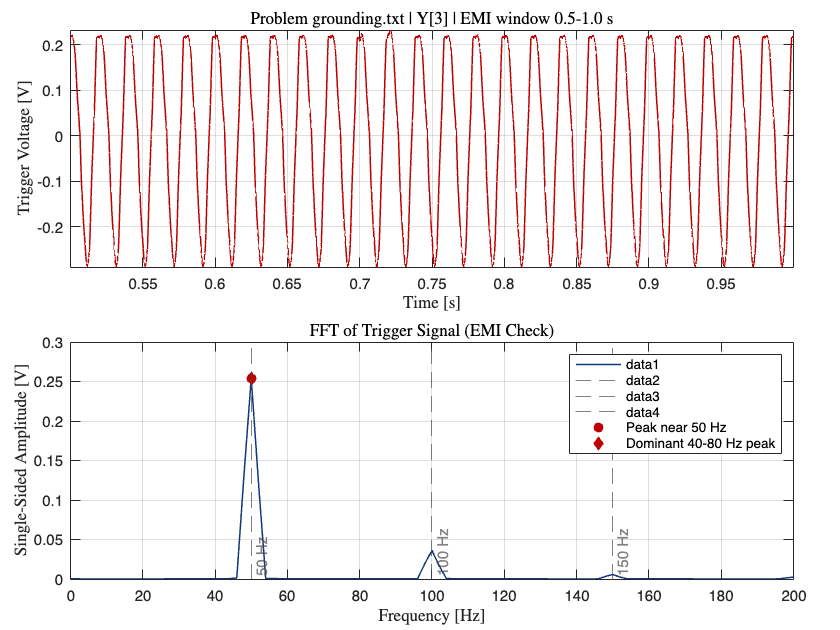


fileName = daqDataEMI.fileName;
chName   = daqDataEMI.channelNames(emiChIdx);
figure;
set(gcf, 'Color', 'w');
tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'compact');

% Top panel: Time domain trigger oscillation
nexttile;
plot(t_emi, y_emi, 'Color', Red_Dark, 'LineWidth', 1.0);
grid on; axis tight;
xlabel('Time [s]', 'Interpreter', 'latex');
ylabel('Trigger Voltage [V]', 'Interpreter', 'latex');
title(sprintf('%s | %s | EMI window %.1f-%.1f s', fileName, chName, emiWindow(1), emiWindow(2)), ...
    'Interpreter', 'latex');

% Bottom panel: FFT magnitude
nexttile;
plot(f_emi, P1_emi, 'Color', LUBlue, 'LineWidth', 1.0); hold on;
xline(50, '--', '50 Hz', 'Color', [0.30 0.30 0.30], 'LabelVerticalAlignment', 'bottom');
xline(100, '--', '100 Hz', 'Color', [0.30 0.30 0.30], 'LabelVerticalAlignment', 'bottom');
xline(150, '--', '150 Hz', 'Color', [0.30 0.30 0.30], 'LabelVerticalAlignment', 'bottom');

if ~isnan(f50_peak)
    plot(f50_peak, A50_peak, 'o', 'Color', Red_Dark, 'MarkerFaceColor', Red_Dark, 'DisplayName', 'Peak near 50 Hz');
end
if ~isnan(f_dom)
    plot(f_dom, A_dom, 'd', 'Color', Red_Dark, 'MarkerFaceColor', Red_Dark, 'DisplayName', 'Dominant 40-80 Hz peak');
end

grid on;
xlim([0, min(200, fs_emi/2)]);
xlabel('Frequency [Hz]', 'Interpreter', 'latex');
ylabel('Single-Sided Amplitude [V]', 'Interpreter', 'latex');
title('FFT of Trigger Signal (EMI Check)', 'Interpreter', 'latex');
legend('Location', 'northeast');

### 2.4 Time Domain Analysis

#### **2.4.1 Baseline/Offset Assessment **

**Objective: **Identify any baseline offset and decide on necessary baseline correction.

**Workflow:**

- select pre-event sample window

- compute per-channel baseline statistics

- decide whether offset removal is required

**Note: **Offset correction based on the** first 100 samples.**

#### **2.4.2 DC-Offset-Correction**

**Objective: **Pressure reading corrected (offset/baseline removed)

**Workflow:**

- estimate baseline from pre-event segment

- subtract baseline from pressure channels

- verify corrected traces preserve event dynamics

% Not Implemented 

#### 2.4.3 Corrected Pressure Signal Summary (DC-Offset-Corrected)

**Objective:** quantify key time-domain metrics from corrected pressure signals (peak overpressure, minimum pressure, timing, impulse, and energy).

**Workflow:**

- use DC-offset-corrected pressure signals

- compute pMax/pMin and corresponding occurrence times

- compute impulse and cumulative impulse check

- compute total signal energy

- compile summary table for cross-test comparison

**Compute Pressure max, and min across each test**

% Not Implemented 

**Compute Impulse and Signal Energy [kPa.ms]**

% Not Implemented

**Impulse Check by Cumulative**

% Not Implemented

**Compute Signal Energy [kPa^2]**

% Not Implemented

**Table Summary**

% Not Implemented


## 3. Preliminary Observations on Data Integrity

### **3.1 Justification for Suspending DC-Offset Correction**

Based on the signal verification steps, the data integrity is currently compromised by three interacting hardware issues, making standard software-based DC offset corrections invalid:

- **Thermal or Time Constant Effect:** In Section 1.2 (Plot Imported Signal Data), it is evident that the pressure signals do not return to the baseline (zero pressure) following the deflagration event. This behavior requires further investigation, including consulting Kistler, to verify whether this offset is an artifact of the system's discharge time constant (tau) or a result of thermal shock to the sensor diaphragm.

- **Trigger Misalignment & Synchronization Failure:** The exact Zero-Time (t=0) is untrustworthy due to DAQ synchronization issues. Without a reliable time reference, defining a "pre-event window" to calculate a baseline offset is arbitrary.

- **Trigger Signal Characteristics (approx. 100ms pulse width):** Visual inspection of the trigger channel reveals a pulse width of exactly 100 ms, which is excessively long for standard DAQ synchronization. Furthermore, while the rising edge is sharp, the falling edge exhibits a slow capacitive discharge curve (RC decay) rather than a clean digital transition to ground. This indicates an unterminated or floating signal line, further highlighting the unrefined state of the electrical synchronization hardware.

- **Ignition Artifacts (Cross-talk):** Section 2.2 revealed that the ignition mechanism firing physically or electrically affects the pressure sensor signals. This cross-talk overlaps with the actual physical pressure wave, meaning peak overpressure (pMax) and impulse calculations would be artificially inflated by electrical noise.

- **Severe Electromagnetic Interference (EMI):** As proven in Section 2.3, the system is contaminated by strong 50 Hz mains interference. 

### **3.2 Hardware Review Recommendations**

To obtain valid pressure readings, impulse metrics, and signal energy calculations, the following physical system reviews are required before further software processing:

- **Grounding and Shielding:** Implement proper isolation for the pressure sensors and DAQ channels to reject the 50 Hz mains EMI.

- **Ignition Isolation:** Optically or galvanically isolate the ignition trigger circuit from the DAQ to prevent high-voltage firing artifacts from bleeding into the sensitive pressure channels.

- **DAQ Synchronization:** Review the hardware trigger routing between devices to ensure a strict, simultaneous t=0 across all streams.

- **Synchronization Protocol Suggestion:** Synchronize the DAQ systems based on the low-voltage Trigger Command rather than the Ignition Event. If precise spark timing is required later, we can integrate a photodiode to optically detect the initial spark or flame kernel.

### **3.3 Postponed Time-Domain Metrics**

Due to the integrity issues documented above, the following calculations are suspended pending hardware corrections:

- DC-Offset estimation and subtraction.

- Peak Overpressure (pMax) and Minimum Pressure (pMin) timing.

- Signal Energy and Cumulative Impulse computations.

## 4. Signal Preprocessing

### 4.1 Selected Test to Filter 

**Objective:** Define the specific test, pressure channel, and analysis time window used for (i) EWT-based spectral segmentation and (ii) low-pass filter sensitivity analysis.

**Workflow:**

- choose test index representative of experiment behavior

- choose target pressure channel for filter tuning

- define analysis time window covering relevant signal dynamics

**Rationale:**

The ignition trigger provides a reproducible time reference (t_trigger). However, the "end of relevance" is not determined by the trigger and may be affected by DAQ chain dynamics (e.g., time constant tau). 

**Therefore, the end time is set explicitly (engineering judgement) as a fixed offset after t_trigger.**

#### 4.1.1 User selections: Selected Data Test & Window Definition

#### 2.3.1 Selected Data

TestIdx = 6;                    % Test used for filter design
DaqIdx  = 1;                    % Standardized DAQ stream
ChIdx = 1;                      % Pressure channel (kPa conversion enabled)
triggerChIdx = 4;               % Trigger channel (volts)
triggerWindow = [0.0, 1.0];     % Search interval for ignition trigger [s]

preTime = 0.000;                 % Window start offset relative to t_trigger [s]
postTime_user = 0.30;           % MANUAL: window end offset relative to t_trigger [s]

plotPad = 0.05;                 % Plotting context padding [s]

% Extract the standardized daqData object
daqData = tests(TestIdx).daqs(DaqIdx).data;

#### 4.1.2 Extract trigger signal (volts) and precondition

[t_trig, y_trig, Fs_trig] = AuxFcn_GetWindowedSignal_001( ...
    daqData, triggerChIdx, triggerWindow, false);

% Mild smoothing to suppress high-frequency noise without materially smearing timing
y_trig_s = movmean(y_trig, max(5, round(0.0005 * Fs_trig)));  % ~0.5 ms

#### 4.1.3 Detect ignition trigger time (robust threshold + persistence)

% Use a robust mid-level threshold based on percentiles (avoids assumptions about absolute voltage levels)
v10 = prctile(y_trig_s, 10);
v90 = prctile(y_trig_s, 90);
thrTrig = 0.5*(v10 + v90);

nPersist = max(10, round(0.001*Fs_trig));  % require persistence for 1 ms
idxCross = find(y_trig_s > thrTrig, 1, 'first');
assert(~isempty(idxCross), 'No trigger crossing found. Check triggerChIdx or triggerWindow.');

idxTrig = [];
for k = idxCross:(length(y_trig_s)-nPersist)
    if all(y_trig_s(k:(k+nPersist-1)) > thrTrig)
        idxTrig = k;
        break;
    end
end
assert(~isempty(idxTrig), 'Trigger did not satisfy persistence condition.');

t_trigger = t_trig(idxTrig);


#### 4.1.4 Define analysis window (LB from trigger; UB manual)

LB_window = max(0, t_trigger - preTime);
UB_window = t_trigger + postTime_user;

Window = [LB_window, UB_window];
assert(Window(1) < Window(2), 'Window must satisfy [tStart < tEnd].');

fprintf('Selected analysis window: LB = %.6f s, UB = %.6f s (duration = %.4f s)\n', ...
    LB_window, UB_window, UB_window - LB_window);

Selected analysis window: LB = 0.300001 s, UB = 0.600000 s (duration = 0.3000 s)


#### 4.1.5 Extract pressure signal within analysis window (convert to kPa = true)

[t_windowed, y_windowed, Fs] = AuxFcn_GetWindowedSignal_001( ...
    daqData, ChIdx, Window, true);

#### 4.1.6 Diagnostic plot (trigger + pressure with selected window)

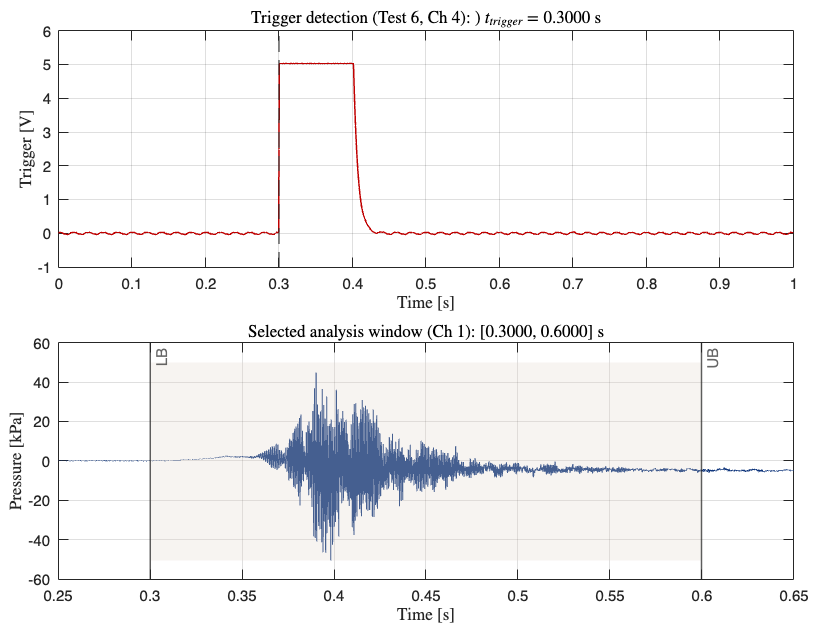

plotWindow = [max(0, LB_window - plotPad), UB_window + plotPad];
[t_pPlot, pPlot, ~] = AuxFcn_GetWindowedSignal_001( ...
    daqData, ChIdx, plotWindow, true);

figure;
tiledlayout(2,1,'TileSpacing','compact','Padding','compact');

% Trigger
nexttile;
plot(t_trig, y_trig_s, 'LineWidth', 1, 'Color',Red_Dark); hold on;
xline(t_trigger, '--', 'LineWidth', 1);
grid on; box on;
xlabel('Time [s]','Interpreter','latex');
ylabel('Trigger [V]','Interpreter','latex');
title(sprintf('Trigger detection (Test %d, Ch %d): ) $t_{trigger}=$%.4f s', ...
    TestIdx, triggerChIdx, t_trigger), 'Interpreter','latex');
hold off;

% Pressure + window
nexttile;
plot(t_pPlot, pPlot, 'LineWidth', 0.5, 'Color',LUBlue); hold on;
yl = ylim;

patch([LB_window UB_window UB_window LB_window], ...
    [yl(1) yl(1) yl(2) yl(2)], ...
    LUCopper_Light, 'EdgeColor','none', 'FaceAlpha',0.25);

xline(LB_window, '-', 'LB', 'LineWidth', 1);
xline(UB_window, '-', 'UB', 'LineWidth', 1);

grid on; box on;
xlabel('Time [s]','Interpreter','latex');
ylabel('Pressure [kPa]','Interpreter','latex');
title(sprintf('Selected analysis window (Ch %d): [%.4f, %.4f] s', ...
    ChIdx, LB_window, UB_window), 'Interpreter','latex');
hold off;

### 4.2 EWT-Guided Cutoff Frequency Identification

#### 4.2.1 Signal Decomposition by MRA using Empirical Wavelet Transform (EWT) 

**Objective: **Obtain a data-adaptive multiresolution analysis (MRA) of the selected pressure signal (y_windowed) and extract the EWT filter-bank passbands [Li, Ui]. These passbands define a data-driven spectral partition used later to build candidate low-pass filter specifications.

**Workflow:**

- run EWT on selected windowed signal

- run EWT with MaxNumPeaks

- convert normalized peak/passband frequencies to Hz

- Verify signal reconstruction and coefficient energy preservation as per MATLAB documentation.

- summarize modes in table and plot original + IMFs

**Notes on terminology: **Multiresolution analysis **(MRA), **Empirical Wavelet Transform **(EWT).**

assert(exist('ewt', 'file') == 2, ...
    'EWT function not available. Requires Wavelet Toolbox with ewt().');

MaxNumPeaks = 10;  % Maximum number of peaks retained in EWT segmentation (MATLAB ewt option)

% Ensure column vectors for consistent behavior
y_ewt = y_windowed(:);

% Run EWT
[mra, cfs, wfb, info] = ewt(y_ewt, 'MaxNumPeaks', MaxNumPeaks);

% Convert normalized peak frequencies and passbands to Hz
PeakFrequencies_Hz = Fs * info.PeakFrequencies(:);

Passbands_Hz = Fs * info.FilterBank.Passbands;   % rows correspond to MRA components
Passbands_Hz = sort(Passbands_Hz, 2);            % enforce [Li Ui] per row

Li = Passbands_Hz(:,1);
Ui = Passbands_Hz(:,2);

#### 4.2.2 Signal Reconstruction and Energy Preservation Verfication (MRA components sum to original signal) (sanity / traceability)

**Reconstruction Error Check**

% Ensure column vector orientation for subtraction
recon = sum(mra, 2);
SignalReconCheck = max(abs(y_ewt(:) - recon(:)));

**Coefficient Energy Preservation Check**

signalEnergy = norm(y_ewt, 2)^2;
cfsEnergy = sum(sum(abs(cfs).^2));
EnergyPreservRelDiffCheck = abs(cfsEnergy - signalEnergy) / signalEnergy * 100;
fprintf('\n--- EWT Mathematical Verification ---\n Reconstruction Error: %.3e (Ideal: < 1e-10)\n', SignalReconCheck);


--- EWT Mathematical Verification ---
 Reconstruction Error: 2.842e-14 (Ideal: < 1e-10)


fprintf('Energy Preservation:  %.3e %% difference\n', EnergyPreservRelDiffCheck);

Energy Preservation:  3.120e-12 % difference


% Active Script Protection (Optional but recommended)
% If the error is larger than typical floating-point precision, halt the script.
assert(SignalReconCheck < 1e-9, 'WARNING: EWT Reconstruction error is abnormally high.');
assert(EnergyPreservRelDiffCheck < 1e-9, 'WARNING: EWT failed energy preservation check.');

#### 4.2.3 Per-component metadata table (passbands + peaks-in-band + energy share)

numMRAComponents = size(mra,2);

% Energy fraction per component (useful for interpretation and later reporting)
modeEnergy = sum(abs(mra).^2, 1).';     % per component
modeEnergyPct = 100 * modeEnergy / sum(modeEnergy);

% Associate detected segmentation peaks to passbands (a band may contain multiple peaks)
peaksInBand = cell(numMRAComponents,1);
nPeaksInBand = zeros(numMRAComponents,1);

for j = 1:numMRAComponents
    inBand = (PeakFrequencies_Hz >= Li(j)) & (PeakFrequencies_Hz < Ui(j));
    peaksInBand{j} = PeakFrequencies_Hz(inBand);
    nPeaksInBand(j) = sum(inBand);
end

EWT_SummaryTable = table( ...
    (1:numMRAComponents).', Li, Ui, modeEnergyPct, nPeaksInBand, peaksInBand, ...
    'VariableNames', {'EWT_MRA_Component','PassbandLow_Hz','PassbandHigh_Hz', ...
    'ModeEnergy_%','NumPeaksInBand','PeaksInBand_Hz'} );

disp(EWT_SummaryTable);

    EWT_MRA_Component    PassbandLow_Hz    PassbandHigh_Hz    ModeEnergy_%    NumPeaksInBand     PeaksInBand_Hz 
    _________________    ______________    _______________    ____________    ______________    ________________

            1                2613.3          1.0417e+05          13.481             1           {[ 2.8300e+003]}
            2                2393.3              2613.3          1.9139             1           {[ 2.4100e+003]}
            3                1756.7              2393.3          4.6889             1           {[ 2.3767e+003]}
            4                  1270              1756.7          5.3518             1           {[ 1.2933e+003]}
            5                1216.7                1270          2.7052             1           {[ 1.2433e+003]}
    

#### **4.2.4 Mechanical Design Recommendations: High-Energy Modal Coupling**

**Observation from EWT Analysis**

While the presence of high-frequency structural ringing is unavoidable in a vented deflagration testing, **the energy distribution revealed by the EWT is highly anomalous.** The bulk deflagration pressure rise (Component 10, 0–270 Hz) accounts for only **25.6%** of the recorded signal energy. Conversely, narrow high-frequency bands—specifically Components 6 and 7 (1.17 kHz to 1.21 kHz)—carry a combined **~39.2%** of the signal energy.

**The Engineering Challenge**

The issue is not the existence of these high frequencies, but the disproportionate level of energy they are transferring into the piezoelectric crystal. When structural resonances dominate the signal energy, the sensor is excessively coupled to the mechanical excitation of the chamber rather than the static gas pressure. To reduce the amplitude and energy transfer of these high-frequency artifacts, the following mechanical design review is recommended:

- **Sensor Mounting Compliance (The "Tuning Fork" Effect):** A protruding or thin-walled mounting boss acts as a mechanical amplifier when struck by the blast wave. The sensor mount literally rings like a tuning fork, violently oscillating the piezoelectric element at its natural frequency.

- **Recommendation:** Increase the physical stiffness of the sensor port (e.g., make it shorter, thicker, or heavily gusseted) to shift its natural frequency significantly higher. Higher frequencies in the shockwave inherently contain less excitation energy, which will drastically reduce the amplitude of the resulting vibration and decouple it from the pressure measurement.

#### 4.2.4 Plot: original signal + first N MRA components

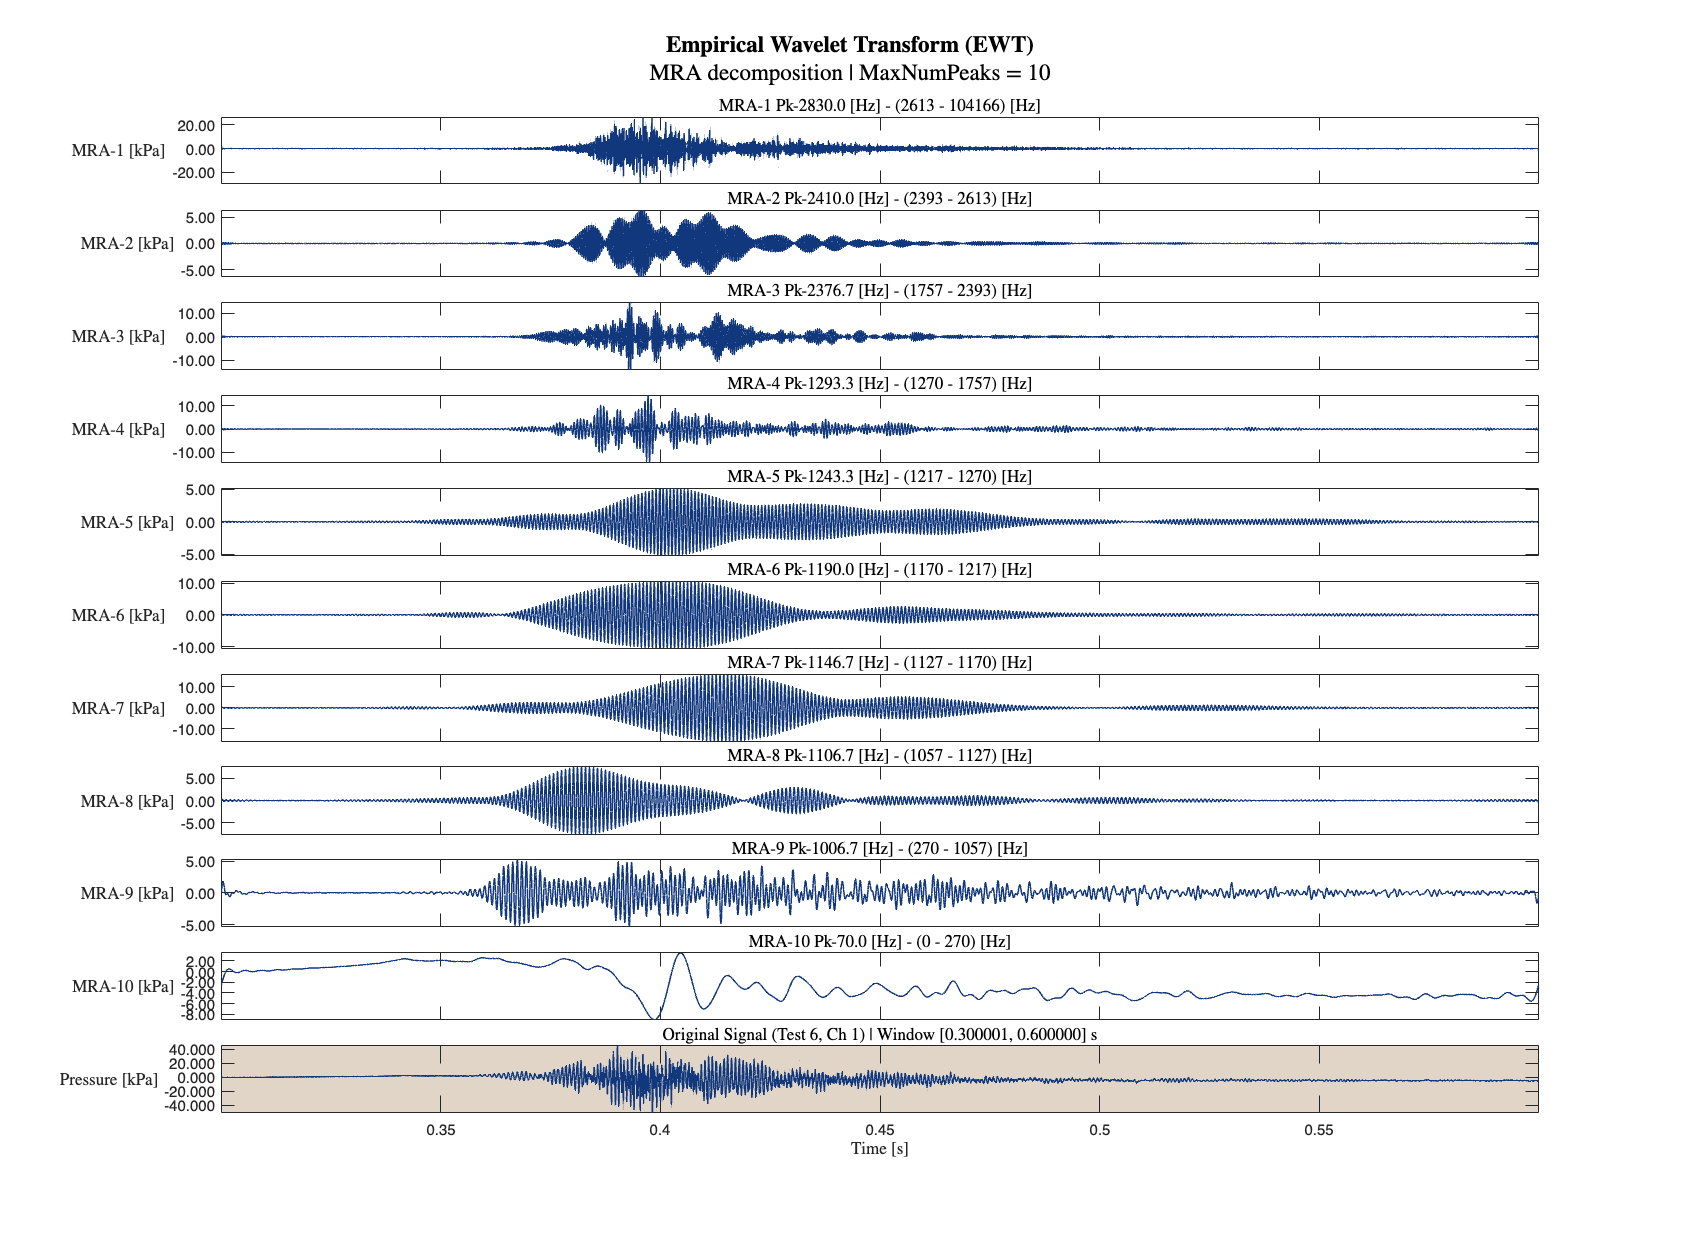

%% Improved EWT/MRA plot (MATLAB order) using your preferred styling/layout
% - Original signal at bottom with background color
% - MRA components on top (MATLAB order)
% - Peak + passband in titles
% - Units on y-axis
% - Consistent y-label orientation/alignment like your example
% - Axis tight and xticklabels suppressed except bottom axis

% --- User control for y-label orientation (match your example style) ---
yLabelRotationDeg = 0;   % 0 recommended (as in your example)

% --- Use MATLAB order directly (no reordering) ---
mra_plot = mra;
Li_plot  = Li;
Ui_plot  = Ui;

numMRAComponents = size(mra_plot,2);
nPlotModes = min(numMRAComponents, MaxNumPeaks);

% Representative peak per component
if ~exist('repPeakHz','var')
    repPeakHz = nan(numMRAComponents,1);
    if exist('PeakFrequencies_Hz','var')
        for j = 1:numMRAComponents
            inBand = (PeakFrequencies_Hz >= Li_plot(j)) & (PeakFrequencies_Hz < Ui_plot(j));
            if any(inBand)
                repPeakHz(j) = PeakFrequencies_Hz(find(inBand,1,'first'));
            end
        end
    end
end

figure
x0=10; y0=10;
width=300;
height=20*(nPlotModes+1);
set(gcf,'units','centimeters','position',[x0,y0,width,height])

% --- Plot original signal at bottom (with background color) ---
signalAx = subplot(nPlotModes+1,1,nPlotModes+1);
plot(t_windowed, y_ewt, 'Color', LUBlue, 'LineWidth', 1);

ytickformat('%.3f')
ax = gca;
ax.YAxis.Exponent = 0;

ylimMax = max(y_ewt);
ylimMin = min(y_ewt);
ylim([ylimMin + ylimMin*0.2, ylimMax + ylimMax*0.2])

signalAx.Color = LUCopper_Light;

ylabel('Pressure [kPa]','Interpreter','latex');
signalAx.YLabel.Rotation = yLabelRotationDeg;
signalAx.YLabel.HorizontalAlignment = 'right';
signalAx.YLabel.VerticalAlignment = 'middle';

title(sprintf('Original Signal (Test %d, Ch %d) | Window [%.6f, %.6f] s', ...
    TestIdx, ChIdx, Window(1), Window(2)), 'Interpreter','latex');

xlabel('Time [s]','Interpreter','latex');
axis tight
box on
grid off

% --- Plot MRA components first (top) ---
for k = 1:nPlotModes
    modesAx = subplot(nPlotModes+1,1,k);
    plot(t_windowed, mra_plot(:,k), 'Color', LUBlue, 'LineWidth', 1);

    ytickformat('%.2f')
    ax = gca;
    ax.YAxis.Exponent = 0;

    ylimMax = max(mra_plot(:,k));
    ylimMin = min(mra_plot(:,k));
    ylim([ylimMin + ylimMin*0.2, ylimMax + ylimMax*0.2])

    ylabel(sprintf('MRA-%d [kPa]', k), 'Interpreter','latex');
    modesAx.YLabel.Rotation = yLabelRotationDeg;
    modesAx.YLabel.HorizontalAlignment = 'right';
    modesAx.YLabel.VerticalAlignment = 'middle';

    if ~isnan(repPeakHz(k))
        peakText = num2str(repPeakHz(k), '%.1f');
    else
        peakText = 'NaN';
    end

    title(sprintf('MRA-%d Pk-%s [Hz] - (%.0f - %.0f) [Hz]', ...
        k, peakText, Li_plot(k), Ui_plot(k)), 'Interpreter','latex');

    axis tight
    box on
    grid off

    % Suppress x tick labels for all MRA subplots (leave only bottom axis)
    set(gca,'xticklabel',[])
end

sgtitle({ ...
    '\textbf{Empirical Wavelet Transform (EWT)}', ...
    sprintf('MRA decomposition | MaxNumPeaks = %d', MaxNumPeaks) ...
    }, 'Interpreter','latex');

#### 4.2.5 Diagnostic Overlay: Raw Signal vs. EWT Baseline

**Objective:** Visually demonstrate the severity of the mechanical coupling.

**Note:** This reconstruction is for visual diagnostic proof only. Quantitative Pmax and dP/dt cannot be reliably extracted.

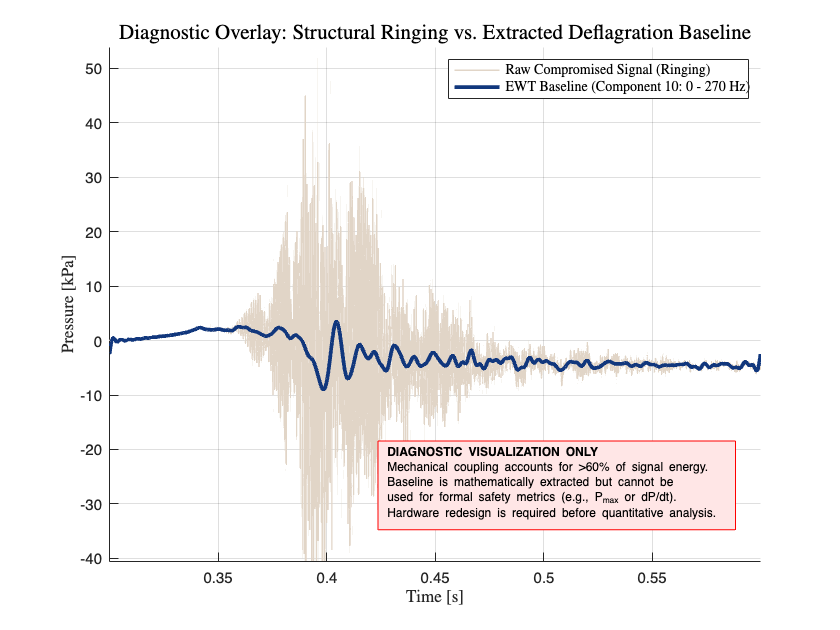

% Isolate the lowest frequency component (the bulk pressure curve)
% From the EWT table, this is the final component (e.g., Component 10)
baselineComponentIdx = 10;
y_baseline = mra_plot(:,baselineComponentIdx);

% Create the diagnostic figure
figure;
set(gcf, 'Color', 'w');
hold on; grid on;
% Plot the raw compromised signal (Light red/pink to sit in the background)
plot(t_windowed, y_windowed, 'Color', LUCopper_Light, 'LineWidth', 1.0, 'DisplayName', 'Raw Compromised Signal (Ringing)');

% Plot the extracted EWT baseline (Bold dark blue)
plot(t_windowed, y_baseline, 'Color', LUBlue, 'LineWidth', 2.5, ...
    'DisplayName', sprintf('EWT Baseline (Component %d: 0 - 270 Hz)', baselineComponentIdx));

% Formatting
xlabel('Time [s]', 'Interpreter', 'latex');
ylabel('Pressure [kPa]', 'Interpreter', 'latex'); 
title('Diagnostic Overlay: Structural Ringing vs. Extracted Deflagration Baseline', 'Interpreter', 'latex',FontSize=14);
legend('Location', 'northeast', 'Interpreter', 'latex');
axis tight;
ylim([min(y_windowed)-0.2*min(y_windowed), max(y_windowed)+ 0.2*max(y_windowed)]);
xlim([min(t_windowed), max(t_windowed)]);

% Add a diagnostic disclaimer textbox directly onto the plot
% Places the box in the lower right, below the legend
dim = [0.45 0.20 0.10 0.10];
str = {'\bf{DIAGNOSTIC VISUALISATION ONLY}', ...
       'Mechanical coupling accounts for >60% of signal energy.', ...
       'Baseline is mathematically extracted but cannot be', ...
       'used for formal safety metrics (e.g., P_{max} or dP/dt).', ...
       'Hardware redesign is required before quantitative analysis.'};
annotation('textbox', dim, 'String', str, 'FitBoxToText', 'on', ...
           'BackgroundColor', [1 0.9 0.9], 'EdgeColor', 'r', 'Interpreter', 'tex',FontSize=8);

#### 4.2.2 Candidate Cutoff Frequency Selection

**Rationale:** The EWT segmentation provides local band limits [Li, Ui] for each extracted component. To avoid placing a physically relevant spectral component at the Butterworth half-power point (−3 dB), we define candidate passband edges fp,i above the upper EWT boundary Ui using a bandwidth-proportional margin. The stopband edge fs,i is then placed one additional local band width above fp,i.

**Definitions:**

- Local EWT band width:    Bi = Ui - Li

- Passband edge (cutoff):  fp,i = Ui + gamma * Bi

- Stopband edge:           fs,i = fp,i + kWidth * Bi

**Robustness constraints:** Impose a minimum transition width (absolute + relative) and enforce fs < Nyquist to prevent ill-conditioned designs (Ws ≈ Wp) and numerical pathologies.

#### User-defined parameters (explicit) 

#### Diagnostic: effect of increasing stop frequency on theoretical order (buttord)

### 4.3 Low-Pass Filter Sensitivity Analysis

#### 4.3.1 Filter-Order and Cutoff Sweep

**Objective: **Quantify sensitivity of integral and peak metrics (signal energy, impulse, peak pressure) to the low-pass specification across EWT-derived candidates and a range of filter orders.

**Workflow:**

-  preliminary filter deisgn. compute minimum Butterworth order for each candidate cutoff

- evaluate a range of filter orders

- compute metric ratios vs unfiltered signal

- select final cutoff using robustness criteria

**Filter Order Design Parameters**

**Performance Metrics**

**Performance Metrics**

**Final cutoff selection rule**

smallest cutoff where all tested orders preserve >=98% impulse and peak.

#### 4.3.2 Summary Table (recommended for traceability)

Diagnostic: effect of increasing stop frequency on theoretical order (buttord)

#### 4.3.3 Sensitivity Plots

### 4.4 Final Filter Design and Phase Delay Effect

#### 4.4.1 Butterworth Filter at Selected Cutoff

**Objective: **design final low-pass filter using the selected EWT-guided cutoff and evaluate phase delay compensation in time domain.

#### 4.4.2 Phase Delay Effect Plot

## 5. Quantity of Interest (QoI) Extraction of **∆Pmax [kPa] after Filtering**

### 5.1 Define CutOff Frequencies & Minimum Filter Order

### 5.2 Calculation **∆Pmax [kPa] after Filtering**

### 5.3 Plot **∆Pmax [kPa] after Filtering**

## 6. Preliminary **Conclusions and Suggestions**

**Synchronization Hardware**

The trigger signal exhibits a 100 ms pulse width with a floating RC-discharge edge, and lacks isolation from 50 Hz mains EMI. 

Suggestion: Further investigation on the appropiated triggering and synchorisation system is required.

**Sensor Baseline Drift**

The charge amplifier setup exhibits severe negative voltage drift (time-constant bleed) prior to ignition, rendering the absolute zero-pressure reference unstable. 

Suggestion: Review the DAQ coupling (AC vs DC) and the Kistler charge amplifier time-constant settings.

**Apparent Severe Mechanical Resonance**

EWT analysis mathematically proves that over 60% of the recorded signal energy exists as structural/acoustic ringing in the kilohertz range, rather than physical gas pressure.

Suggestion:* Redesign the sensor mounting boss to increase structural stiffness to reduce vibration effects before further testing.*

## **Note: The Purpose of the Hanning Window**

### **Problem (Spectral Leakage)**

 When a DAQ system records a finite block of data (e.g., a 0.5-second window of a signal), it inherently captures a snapshot of a longer process. The FFT algorithm, however, assumes that this finite block is exactly one period of an infinitely repeating signal. At the boundaries where the block ends and would theoretically repeat, there is almost always a discontinuity between the last sample and the first sample. These abrupt jumps introduce artificial frequency components that smear the true energy from actual frequencies (like a 50 Hz EMI peak) across neighboring bins.

### **Solution**

We apply a Hanning (Hann) window—a smooth, bell-shaped mathematical taper—to the entire recorded data block before computing the FFT. This gently attenuates the signal amplitude to exactly zero at both the beginning and end of the block.

### **Result **

With both ends tapered to zero, the discontinuity at the block boundaries is eliminated. When the FFT implicitly repeats the block, the ends connect seamlessly. This reduce spectral leakage, keeping the 50 Hz EMI peak sharp, isolated, and accurately quantified in the frequency domain.

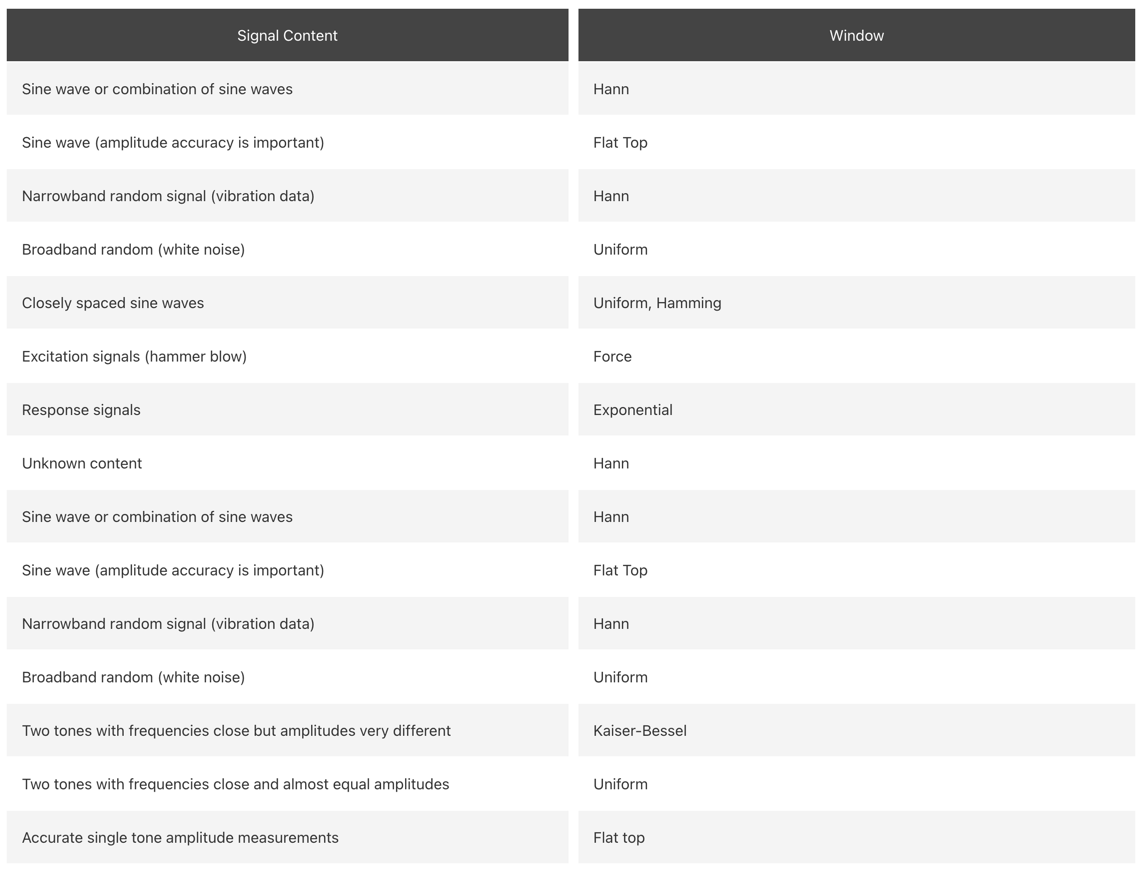

### Summary (source:**Understanding FFTs and Windowing **https://www.ni.com/)

- All signals in the time domain can be represented by a series of sines.

- An **FFT transform** deconstructs a time domain representation of a signal into the frequency domain representation to analyze the different frequencies in a signal.

- The **frequency domain** is great at showing you if a clean signal in the time domain actually contains cross talk, noise, or jitter.

- **Spectral leakage** is caused by discontinuities in the original, noninteger number of periods in a signal and can be improved using windowing.

- **Windowing** reduces the amplitude of the discontinuities at the boundaries of each finite sequence acquired by the digitizer.

- No window is often called the uniform or rectangular window because there is still a windowing effect.

- In general, the **Hanning window** is satisfactory in 95 percent of cases. It has good frequency resolution and reduced spectral leakage.

- You should compare the performance of different window functions to find the best one for the application.

**References**

- **Chapter 13: "Digital Signal Processing Tricks", Understanding Digital Signal Processing **Third Edition Richard G. Lyons. Prince Hall, 2010

**Web Sites: **

- **Understanding FFTs and Windowing **[https://www.ni.com/en/shop/data-acquisition/measurement-fundamentals/analog-fundamentals/understanding-ffts-and-windowing.html](https://www.ni.com/en/shop/data-acquisition/measurement-fundamentals/analog-fundamentals/understanding-ffts-and-windowing.html)

- **Understanding the Hanning Window: A Practical Guide for Beginners **[https://wraycastle.com/blogs/knowledge-base/hanning-window](https://wraycastle.com/blogs/knowledge-base/hanning-window)

## Note on Multiresolution analysis **(MRA) **Empirical Wavelet Transform **(EWT).**

#### General Considerations

**1. Deflagration Pressure Signals Have Dominant Low-Frequency Components**

- The **overpressure rise** in deflagration events is often **gradual** compared to high-frequency noise.

- The **dominant physical processes** (combustion expansion, flame acceleration, venting effects) evolve on timescales much longer than **sensor vibrations or electronic noise**.

**2. Common Sources of High-Frequency Noise**

- **Sensor Vibrations & Structural Resonances:**

- Pressure transducers, particularly those mounted on rigid test chambers, can pick up **high-frequency mechanical vibrations**.

- **Electrical Noise:**

- Data acquisition (DAQ) systems and amplification circuits introduce **high-frequency interference**.

- **Shock-Induced Transients (if present):**

- If a strong shock develops, it may introduce **high-frequency components**, but **for deflagrations**, most of the pressure signal energy is **low-frequency**.

**3. Why a Low-Pass Filter is Appropriate?**

- The primarily interested in: 

- **Peak overpressure** **∆Pmax**

- **Impulse (integral of pressure over time)**

- **Time of peak pressure, **not as relevant as ∆Pmax, however, it is still considered a good metric to consider in the evaluation of the Low-Pass FIlter Effect during the Data Processing Procedure.

- These **key metrics** are **not affected by removing high-frequency noise**.

- A properly chosen **low-pass cutoff frequency** ensures the removal unwanted noise while **preserving** the physically meaningful pressure rise.

**4. Consideration for Cutoff Frequency Selection**

This is a challenge aspec of th edata processing due to the lack of knlodges about the frequencies a that migh tdominate the phenomena, however, several assumption required to be made.

- The **filter cutoff frequency** should be: 

- **Well above** the dominant deflagration pressure rise rate.

- **Below** the typical noise frequency components.

- A **frequency-domain analysis** (FFT or EWT) of the raw pressure signal) help to **identify the frequencies present in each test and determine** an **appropriate cutoff frequency.**

**Remark**

**Applying a low-pass filter makes sense** for the deflagration experiments **as long as the cutoff frequency is chosen appropriately**. 

To ensures that it is captured the **pressure response** while removing high-frequency noise that does not represent physical pressure changes.

#### Empirical Wavelet Transform (EWT) [3]

**Extracted from Matlab**

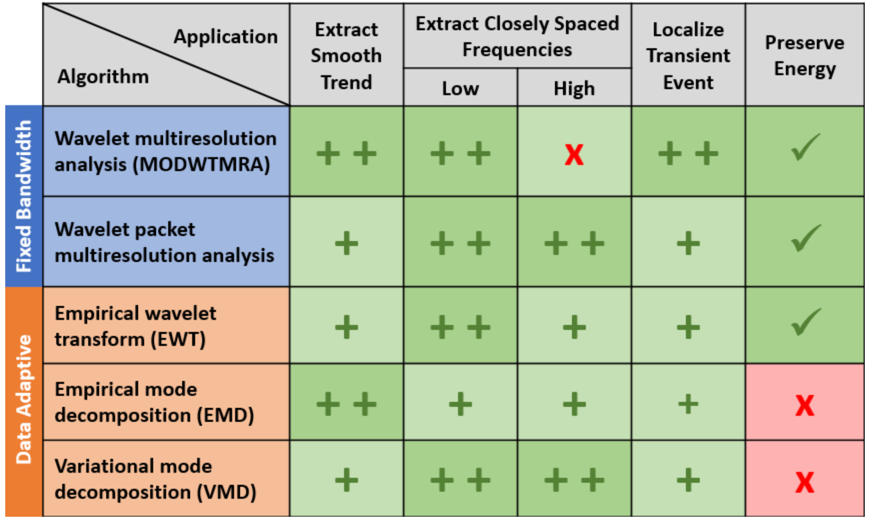

The key thing to note is that similar to the wavelet and EMD decompositions, VMD segregates the three components of interest into completely separate modes or into a small number of adjacent modes. All three techniques allow you to visualize signal components on the same time scale as the original signal. There is a data-adaptive technique which actually constructs wavelet filters based on the frequency content of the data. This technique is the *empirical wavelet transform *(EWT) [3]. One of the major criticisms of EMD is that its definition is purely algorithmic. As a result, it is not readily amenable to mathematical analysis. EWT on the other hand actually constructs Meyer wavelets based on the frequency content of the analyzed signal. Accordingly, the results of EWT are amenable to mathematical analysis because the filters used in the analysis are available to the user. Repeat the analysis of the synthetic signal using the EWT.

**References**

[1] Dragomiretskiy, Konstantin, and Dominique Zosso. “Variational Mode Decomposition.” *IEEE Transactions on Signal Processing* 62, no. 3 (February 2014): 531–44. [https://doi.org/10.1109/TSP.2013.2288675](https://doi.org/10.1109/TSP.2013.2288675).

[2] Flandrin, P., G. Rilling, and P. Goncalves. “Empirical Mode Decomposition as a Filter Bank.” *IEEE Signal Processing Letters* 11, no. 2 (February 2004): 112–14. [https://doi.org/10.1109/LSP.2003.821662](https://doi.org/10.1109/LSP.2003.821662).

[3] Giles, J. "Empirical wavelet transform", *IEEE Transactions on Signal Processing, *vol. 61, no. 16 (May 2013): 3999 - 4010. 

[4] Huang, Norden E., Zheng Shen, Steven R. Long, Manli C. Wu, Hsing H. Shih, Quanan Zheng, Nai-Chyuan Yen, Chi Chao Tung, and Henry H. Liu. “The Empirical Mode Decomposition and the Hilbert Spectrum for Nonlinear and Non-Stationary Time Series Analysis.” *Proceedings of the Royal Society of London. Series A: Mathematical, Physical and Engineering Sciences* 454, no. 1971 (March 8, 1998): 903–95. [https://doi.org/10.1098/rspa.1998.0193](https://doi.org/10.1098/rspa.1998.0193).

[5] Percival, Donald B., and Andrew T. Walden. *Wavelet Methods for Time Series Analysis*. Cambridge Series in Statistical and Probabilistic Mathematics. Cambridge ; New York: Cambridge University Press, 2000.

*Copyright 2019 The MathWorks, Inc.*